# Dimensionality Reduction and State-Space Systems: Forecasting the  Term Structure of Interest Rates Using the Diebold-Li Model

I have fit the Diebold-Li model of yield curve to a time series of monthly values of yield curves derived from the US Treasury yields ranging from 3 months to 30 years. Firstly, I have representated the Diebold-Li model in a parametric state-space form. Having estimated, simulated, smoothed and forecasted using the state-space models (SSM) as described in Diebold, Rudebusch, Aruoba (2006), I compared the results with those from the two-step method described in Diebold and Li (2006).  Lastly, I have simulated the yield curve using Monte Carlo and forecasted using the minimum mean square error (MMSE) technique embedded in the [SSM functionalities](https://www.mathworks.com/help/econ/ssm-class.html) from the Econometrics toolbox. 

## The Diebold-Li Model of the Yield Curve 

A variant of the Nelson-Siegel model, the Dynamic Nelson Siegel (DNS) or the Diebold-Li model is a reparameterization of the original equation. Given the time to maturity $\tau$, and date $t$ when the yield is observed, the yield $y_t(\tau)$from the Diebold-Li model is a function of four parameters: 


$$y_t(\tau) = L_t + S_t \left(\frac{1 - e^{-\lambda \tau}}{\lambda \tau} \right)
+ C_t \left(\frac{1 - e^{-\lambda \tau}}{\lambda \tau} - e^{-\lambda \tau} \right)$$
              
$$\left(1\right)$$


Here, $L_t$ is the level or the the long-term factor as it influences long-term bonds, $S_t$ is the slope or short-term factor, and $C_t$ is the curvature or the medium-term factor.  $\lambda$ determines the maturity at which the loading on the curvature is maximized, and governs the exponential decay rate of the model. 

After specifying the parametric form of an SSM, I have used MLE to estimate the model's parameters, caliberated the smoothed and filtered states by forward and backward recursion, respectively. Thereafter, Iacquired the optimal forecasts of the observed data and latent states, and employed Monte Carlo to simulate the trajectories of the yield curve and latent states.

## Diebold-Li Model in the State-Space System

The level, slope and curvature in the Diebold-Li model follow a first order vector autoregressive process or VAR(1), which has a state-space representation as follows: 


$$ \pmatrix {L_t - \mu_L \cr S_t - \mu_S \cr C_t - \mu_C}
= \pmatrix {a_{11} \ a_{12} \ a_{13} \cr a_{21} \ a_{22} \ a_{23}
\cr a_{31} \ a_{32} \ a_{33}}
\pmatrix{L_{t-1} - \mu_L \cr S_{t-1} - \mu_S \cr C_{t-1} - \mu_C}  + 
\pmatrix {\eta_t(L) \cr \eta_t(S) \cr \eta_t(C)}  $$


The corresponding measurement equation is: 


$$ \pmatrix{y_t(\tau_1) \cr y_t(\tau_2) \cr \vdots \cr
y_t(\tau_M)} =
\pmatrix{1 \ \frac{1 - e^{-\lambda \tau_1}}{\lambda \tau_1} \ 
\frac{1 - e^{-\lambda \tau_1}}{\lambda \tau_1} - e^{-\lambda \tau_1} \cr
1 \ \frac{1 - e^{-\lambda \tau_2}}{\lambda \tau_2} \ 
\frac{1 - e^{-\lambda \tau_2}}{\lambda \tau_2} - e^{-\lambda \tau_2} \cr
\vdots \cr
1 \ \frac{1 - e^{-\lambda \tau_M}}{\lambda \tau_M} \ 
\frac{1 - e^{-\lambda \tau_M}}{\lambda \tau_M} - e^{-\lambda \tau_M}}
\pmatrix {L_t \cr S_t \cr C_t} 
+ \pmatrix {\epsilon_t(\tau_1) \cr \epsilon_t(\tau_2) \cr \vdots \cr
\epsilon_t(\tau_M)} $$


In matrix notation, we can write the state-space system for the three-dimensional vector of the mean adjusted factors  $f_t$ and observed yields $y_t$: 


$$(f_t - \mu) = A(f_{t-1} - \mu) + \eta_t$$



$$y_t = \Lambda f_t + \epsilon_t$$


$\eta_t$ and $\epsilon_t$ are orthogonal to each other and follow white noise processes and we can write their distribution as: 


$$\left\lbrack \begin{array}{c}
\eta_t \\
\epsilon_t 
\end{array}\right\rbrack \sim \textrm{WN}\left(\;\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
\Sigma_{\eta }  & 0\\
0 & \Sigma_{\epsilon } 
\end{array}\right\rbrack \right)\;$$


The factor disturbances  $\eta_t$ are correlated with each other, causing the covariance matrix $\Sigma_{\eta }$ to be non-diagonal. In juxtaposition, the disturbances $\epsilon_t$ in the observation equation are uncorrelated, yielding a diagonal  covariance matrix $\Sigma_{\epsilon }$. 

The mean-adjusted factors describe the latent states:


$$x_t = f_t - \mu$$


The yields are demeaned or adjusted for intercept


$$y'_t = y_t - \Lambda\mu$$


Susbtituting these in the aforementioned equations, the state-space system of the Diebold-Li model can be characterized as: 


$$x_t = Ax_{t-1} + \eta_t$$



$$y'_t = y_t - \Lambda\mu = \Lambda x_t + e_t$$


In simplistic terms, we can describes the state-space system as follows:


$$ x_t = A x_{t-1} + B u_t $$



$$ y_t = C x_t + D v_t $$


The first and second equations are state and measurement/observation equations, respectively. The state transition matrix $A$ i matches with that of the matrix $A$ in the Diebold-Li formulation, while $\Lambda$ is equivalent to the state measurement sensitivity matrix $C$ in the SSM formulation.

Unlike the straightforward relationship of state transition and measurement sensitivity matrices with those in the Diebold-Li state-space system, the disturbances have a more sophisticated relationship, leading to a subtle parameterization of the $B$ and $D$ matrices. We observe that that the disturbances of the Diebold-Li state space system equate with those in the SSM functionality. 


$$$\eta_t = Bu_t$$



$$\epsilon_t = Dv_t$$


As the disturbances $u_t$ and $\epsilon_t$ are unit-variance, uncorrelated, white noise vector processes, their covariance matrices are identity matrices. Therefore, we relate the parameters of the SSM function ot the covariance of the Diebold-Li model such that:


$$\Sigma_\eta = BB'$$



$$\Sigma_\epsilon = DD'$$


Representing the Diebold-Li model in the state-space system, I have created the SSM implicitely by enumerating  a parameter mapping function whereby a vector of input parameters is mapped to parameters$A$, $B$, $C$, and $D$ of the model. I have employed a mapping function as the three latent factors in the Diebold-Li model are demeaned, which forms a common regression component. Additionally, the mapping function ensures that the $\Sigma_\eta = BB'$ is symmetric, the covariance matrix $\Sigma_\epsilon = DD'$ is diagonal. Finally, the mapping function estimates the decay parameter $\lambda$. Implicitely, the mapping function specifies the model. This is advantageous as we can estimate convoluted models and impose multiple constraints on the parameters. 

Moreover, I have demeaned the yields $y_t$ as the SSM functions such as `filter`,  `smooth`, `forecast`, and `simulate`, assume that observations are already manually demeaned. While estimating, a parameter mapping function deflates the yields observed. The upside is that it maintains the three-dimensionality of the latent factors in the state vector. Nonetheless, the downside is that I have to separately deflate and subsequently inflate the yields to offset the adjustment from estimating on the demeaned yields. 

## The Yield Curve Data

I have aggregated the monthly data on the treasury yields of various maturities, ranging from 3 month to 30 years from [FRED](https://fred.stlouisfed.org/). Depicting a snapshot of the current yield levels in the market, each of the ten series has both a cross-sectional and a temporal dimension. 

In another dataset, I aggregated not only the monthly treasury yields but also other monetary variables that affect the yield curve - 7 measures of yield spreads, such as the TED spread, term premium on zero-coupon bonds of maturities randing from 1 to 10 years, U-3 unemployment rate, inflation rate measured via the personal consumption expenditures, and the year to year change in total capacity utilization (TCU). Then, I performed PCA in all the aforementioned variables except unemployment rate and change in TCU. In total, this dataset has 29 variables. 

% has data from October 31, 1993 to August 30, 2020 collected from FRED
% no missing values
tres = readtable("data_df.csv");
tres_big = readtable("big_data.csv");



% extract the "Dates" column and store it as "dates" table
dates = table2array(tres(:, 'Date')); 

% extract column names of table "tres"
tres.Properties.VariableNames;
tres_big.Properties.VariableNames;

% removes the "Date" column from "tres"
tresc= removevars(tres,{'Date'});
data = table2array(tresc);


% removes the "Date" and other columns from "tres_big"
tresc_big= removevars(tres_big,{'Date', 'tcu_ch', 'unrate'});
%format shortG
data_big = table2array(tresc_big);


% DataTable: has columns' names of yields of varying ttm
% and row names for each date

% yields of 10 term to maturity (TTM) in months
ttm =[3; 6; 12; 24; 36; 60; 84; 120; 240; 360];

% yields = dataset on 10 different maturities for in-sample modeling
yields = data(1:end,:);      % in-sample yields for estimation

% yields_big = dataset on 10 different maturities + other 55 vars for in-sample modeling
yields_big = data_big(1:end,:);      % in-sample yields for estimation


The summary statistics of the treasury yields indicate that on average short-term yields (such as 3, 6 and 12 months yields) are less than long-term yields (such as 120, 240, and 360 months yields). This is because investors require extra compensation or risk premium as an incentive to hold securities for longer duration as longer term yields have more inflation and default risks than the short term yields.  Moreover short-terms fluctuate more as they have higher standard deviations than their long-term counterparts. 

% Summary stats of the latent variables from the Diebold-Li model (DNS)


tab_tres=table();
tab_tres.Min=min(yields)';
tab_tres.Median=median(yields)';
tab_tres.Mean=mean(yields)'; 
tab_tres.Max=max(yields)';
tab_tres.Std_dev=std(yields)';
tab_tres.Properties.RowNames = {'3', '6', '12', '24', '36', '60',...
    '84', '120','240', '360'};

disp_sumstat_tres = {"Summary Statistics of the Treasury Yields:";...
    "----------------------------------";...
    tab_tres};
cellfun(@disp,disp_sumstat_tres)

Summary Statistics of the Treasury Yields:
----------------------------------
           Min     Median     Mean     Max     Std_dev
           ____    ______    ______    ____    _______

    3         0    1.765     2.3889    6.38    2.1401 
    6      0.03     1.89     2.5141    6.51    2.1797 
    12     0.09      2.1     2.6354     7.2     2.187 
    24     0.11    2.405     2.8809    7.69    2.1794 
    36     0.11     2.58     3.0744     7.8    2.1101 
    60     0.21    3.135     3.4426    7.83    1.9542 
    84     0.39    3.555     3.7441    7.84    1.8429 
    120    0.55     3.99       3.98    7.91    1.7181 
    240    0.98    4.635     4.4922     8.1    1

## **Two-Step Principal Components Approach**

After aggregating the yields of various maturities and other monetary variables, I reduced the dimensionality of the dataset by performing PCA.  Thereby, I linked the factors of the yield curve to the macroeconomic factors extracted from the larger dataset comprising of monetary, labor, and output variables. I have written the code to manually perform the PCA, and then I compared the results with those from MATLAB's built-in "pca" function. Following are the steps that I employed in doing the factor analysis:

- First, I demeaned (or mean centered) the data to ensure that all the variables are in the same scale and don't have have large variances and range. This ensures that the range of continuous variables contribute equally to the analysis. As PCA is sensitive to variances, mean centering precludes the variables with larger ranges to dominate those with smaller ranges.

- Secondly, I calculated a $\left(10\times 10\right)$ dimension of covariance matrix of the ten demeaned yields to find which which variables of the demeaned yields vary from each other with respect to the means. The correlation matrix informs the variables that are highly correlated, and consequently, have more redundant information. 

- As the variables from the previous step are correlated with other, I have now rotated the coordinate system to create a new set of variables (principal components) which are uncorrelated with each other, i.e. have zero covariance. From the covariance matrix, I computed the eigenvalues and the eigenvectors. This step diagonalizes the covariance matrix, decorrelating the relationship between the new variables. So, the off-diagonal entries are 0, and the diagonal entries are the eigenvalues, which are the variances of theeir corresponding eigenvectors. 

- Now, I have sorted the eigenvalues in the new coordinate system in the decreasing order of variances. Thereby, I have arranged the PCs such that the $\textrm{PC1}$ explains the maximum variation present in the demeaned yields. Each PC is a linear combination of the mixtures of demeaned yields, and each $\textrm{PC}\;i,i>1$ explains the remaining variation in the dataset. 

- Finally, I caliberated the proportion of variance explained by each $\textrm{PC}\;i$.

Unlike the original and demeaned yields, each principal component (PC) is orthogonal to each other, i.e. each $\textrm{PC}\;i$ has zero covariance with $\textrm{PC}\;j$ where $i\not= j\ldotp$Thus, the off-diagonal entries of the correlation matrix is 0. The first three PCs or the latent factors$-\;\textrm{PC1},\textrm{PC2},\textrm{PC3},$ are also refered to as the level, slope, and curvature factors, respectively. The scree plot shows that the level and slope factors explain $83\ldotp 52,$ and $13\ldotp 34$ percent of variances, respectively. 

% deman the data (subract the mean of each column with the column's
% respective observation
% zero-centers the columns or standardizes the range of continuous vars
demeaned_yields =  yields_big - mean(yields_big);

% covariance matrix of the demeaned yields
% diagonal entries are the variances and off-diagonals are covariance
covariance = cov(demeaned_yields);

% % calculate eigenvectors, and eigenvalues of the covariance matrix
% eigenval_diag: diagonal matrix of eignevalues 
% diagonalized matrix due to 0 covariances but non-0 variances 
% here, covariance * eigvector = eigvector * eigval_diag
[eigvector, eigval_diag] = eig(covariance);
 
% eigval: extracts eigenvalues (diagonal entries of eigval_diag) 
% and stores them as a column vector   
% eigenvalues of the diagonalized matrix are the variance of the PCs in the
% rotated coordinate system
eigval = diag(eigval_diag);


% sort in decreasing order of eigenvalue (variance of the PCs)
% store the indices of which columns the sorted eigenvalues come from
[eigval, indices]=sort(eigval,'descend'); 

% arrange the eigenvectors (PCs) in the descreasing order of their
% corresponding eigenvalues (variances) 
eigvector = eigvector(:,indices); 

% generate PCA component space (PCA scores)
PCs = demeaned_yields * eigvector; 

% variance explained by each of the first 10 PCs
var_explained = var(PCs)/sum(var(PCs)).'; var_explained = var_explained.';
var_explained10 = var_explained(1:10, :);

colNames = {'Variance Explained'};
var_explained_tab = array2table(var_explained10,'VariableNames',colNames)

var_explained_tab = 10×1 table
    Variance Explained
    __________________

           0.83516    
           0.13338    
          0.013566    
          0.011754    
         0.0030352    
         0.0017958    
        0.00060942    
        0.00029256    
        0.00020809    
        6.7516e-05    



% first three principal component score vectors are:
% PCs(:, 3) = -1 * PCs(:,3);
PCs3 = PCs(:,1:3);


Next, I have depicted a plot of variance explained by each PC, wherein the graph displays that $\textrm{PC1}$and $\textrm{PC2}$ explain  majority of the variances in the dataset, compared to the subsequent PCs. 

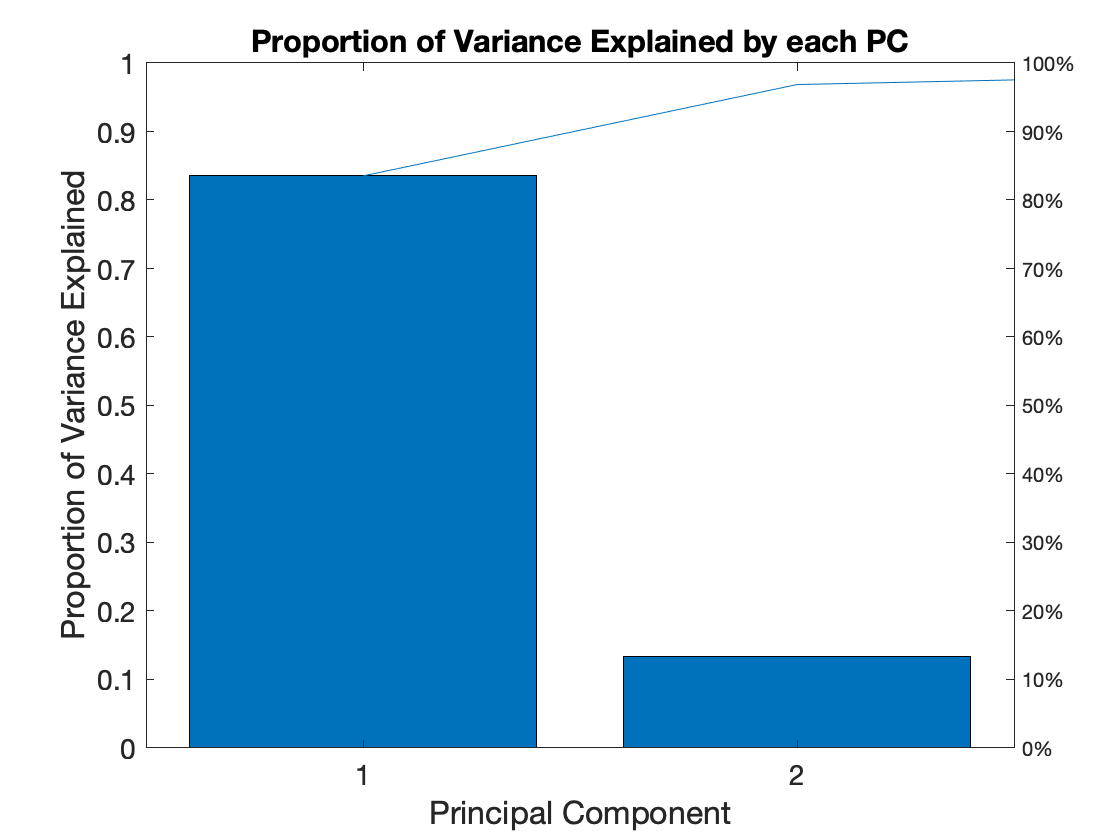

% Scree plot that displays the percentage of variance explained by the
% first few PCs.
figure()
pareto(var_explained)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',14)
xlabel('Principal Component', 'FontSize', 16)
ylabel('Proportion of Variance Explained', 'FontSize', 16)
title('Proportion of Variance Explained by each PC', 'FontSize', 18)

% PCA USING BUILT-IN MATLAB FUNCTION

%  loadings: weights for each original variable when calculating the PC.
% scores: the original data in a rotated coordinated system defined by the PC.
% The score matrix is the same size as the input data matrix.
%  PC i.e. the eigenvalue of the covariance matrix of yields
% explained: percentage of total variance that each PC explains
% mean: estimated means of the PCs in yields

%  [~, score,~, ~, explained, avg] = pca(yields_big)
%  
% % first three principal component score vectors are:
%  pc = score(:,1:3);
%  
% %  column names of the table with first 3 PCs "pc_table"
%  pc_heading = {'PC1' 'PC2' 'PC3'};
%  
% fig = figure('position',[200 200 400 180]);
% pc_table=uitable('parent',fig,'data',pc,'columnname',pc_heading, ...
% 'columnwidth',{100},'position',[10 10 350 170]);
% 
% % Scree plot that displays the percentage of variance explained by the first few PCs.
% % figure()
% % pareto(explained)

## Two-Step Diebold-Li Model with Fixed $\lambda$

Finding the ex-ante value of the latent factors is tantamount to finding the ex-ante values of the yield curve as it is a function of the factors. Then, I have constructed the Diebold-Li model with the explanatory variables as factor forecasts. The two-step approach of fitting the Diebold and Li model and estimating the parameters of their yield curve is:

- Firstly, I have kept $\lambda$ fixed and estimated the level, slope, and curvature parameters for each of the daily values of the yield curve. We can  consider the regression coefficients from OLS as the as the three factors. Repeating this process for all observed yield curves yields a three-dimensional matrix of estimates of the three latent factors. Keeping $\lambda$ fixed simplifies the estimation method from non-linear least squares to OLS, which creates a static Nelson Siegel model at each month.

- Secondly, I have fitted $\textrm{VAR}\left(1\right)$ to the time series of factors derived in the first step.

In the Nelson-Siegel model, $\lambda_t$ determines the time to maturity at which the loadings on the curvature, or the medium-term factor are maximized. These are usually yields that mature in 24 to 36 months.  Diebold and Li (2005) set $\lambda_t =0\ldotp 0609\;$ for all $t$ as it maximizes the curvature loadings maturing in 30 months (average of 24 and 36 months). However, their dataset ranges from January 1985 to December 2000, while the analysis of this dataset is based on time series from October 1993 to August 2020.  Using  $\lambda_t =0\ldotp 0609\;$in this dataset will mazimize the curvature loadings in exactly 28.47 months, therefore I set $\lambda_t =0\ldotp 0598,$ as it maximizes the  medium-term loadings in precisely 30 months. Below, I have shown the first-step in the Diebold-Li model, and accumulated the coefficients (factor loadings) and the residuals from the OLS model. The factor loadings on $L_t ,S_t$ and $S_t$ govern the level, slope and curvature, respectively, of the yield curve. In the dynamic version of the Nelson-Siegel model represented below, I multiplied the time-varying slopes$-L_t \;,S_t$ and $C_t$ with the factor loadings. 


$$y_t \left(\tau_m \right)=L_t +S_t \left(\frac{1-e^{-\lambda \tau_m } }{\lambda \tau_m }\right)+C_t \left(\frac{1-e^{-\lambda \tau_m } }{\lambda \tau_m }-e^{-\lambda \tau_m } \right)$$


Then, I plotted the factor loadings in one graphs. 

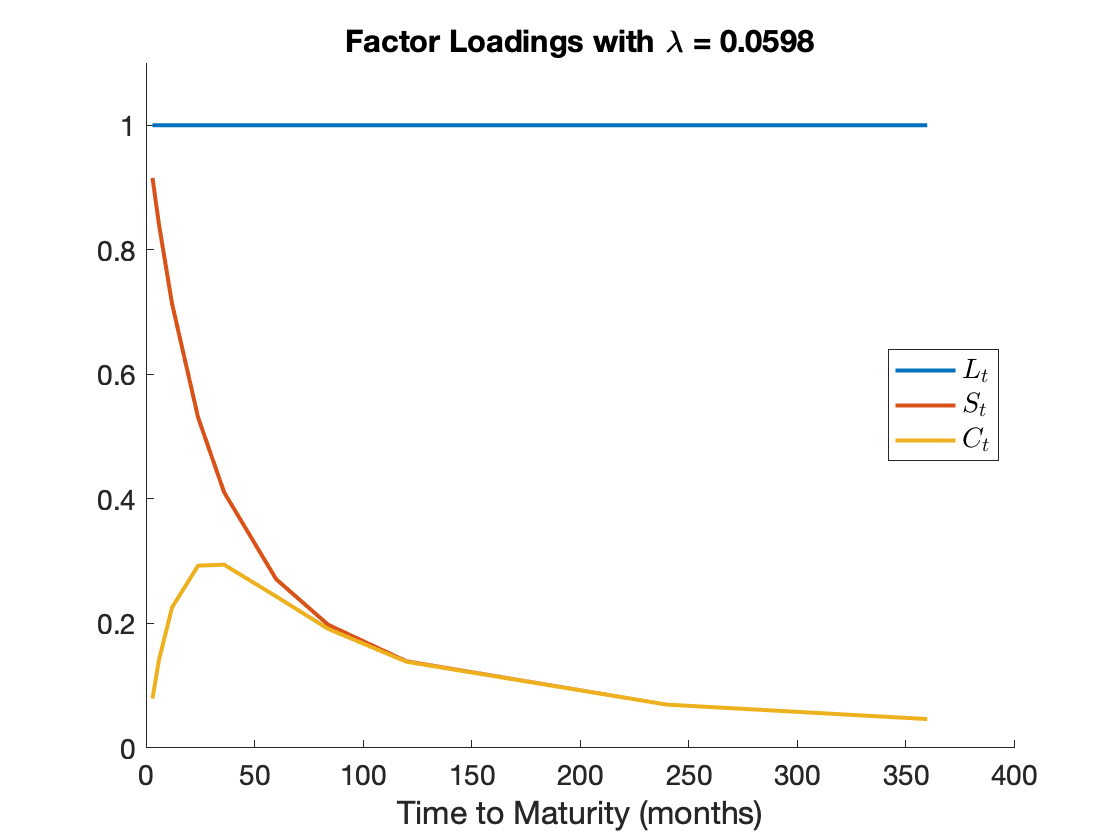

lambda0 = 0.0598;

% X is a 10 by 3 matrix: as there is data on 10 different yields and 3 beta
% factors
X = [ones(size(ttm)) (1-exp(-lambda0*ttm))./(lambda0*ttm) ...
    ((1-exp(-lambda0*ttm))./(lambda0*ttm)-exp(-lambda0*ttm))];


% size(yields,1): queries the length of the 1st dim of 'yields" : 324
% beta = zeros(324, 3): 324 x 3 matrix of 0s (placeholder)
% after OLS, beta is stored with estimated slope coefficients
beta = zeros(size(yields,1),3);

% numel : returns the number of elements in array "ttm" : 10
% resid = zeros(324, 10): 324 x 3 matrix of 0s
% stores the resid from the OLS model
resid = zeros(size(yields,1),numel(ttm));

% fix lambda and compute the 3 beta params for each monthly observation of the
% yield curve by OLS
% the beta coefficients from the OLS regression are equivalent to the 3
% factors: level, slope, and curvature
% collect the 3D time-series of the betas (estimated factors) by fitting
% the OLS model on each yield curve observed
% store the betas (regression coefficients) and resid

for i = 1:size(yields,1) 
    OLSmod = fitlm(X, yields(i,:)', 'Intercept', false);
    beta(i,:) = OLSmod.Coefficients.Estimate';
    
    % raw residuals (observed - fitted values) from the OLS model 
    resid(i,:) = OLSmod.Residuals.Raw'; 
end


% Plot the factor loadings
figure
hold on
plot(ttm,X, 'LineWidth', 2)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',14)
title('Factor Loadings with \lambda = 0.0598', 'FontSize', 18)
xlabel('Time to Maturity (months)','FontSize',16)
ylim([0 1.1])
legend({'$L_t$';'$S_t$';'$C_t$'}, 'FontSize',14,...
    'Interpreter', 'latex','location','east')
hold off

$L_t$ is a flat line parallel to the maturity axis, that represents the level factor in the Diebold-Li equation $\left(1\right)\ldotp$ The loadings on  $S_t$ is a function $\frac{1-e^{\lambda \tau } }{\lambda \tau }$ , that starts at 1 approximately but monotonically decays to 0; therefore, it is a convex-shaped curve. Finally, the loadings on $C_t$ is a function $\frac{1-e^{\lambda \tau } }{\lambda \tau }-e^{-\lambda \tau }$ that starts at 0 and gradually converges to 0, affecting the medium-term yields. $\lambda_t$ governs the pace of exponential decay wherein small values of $\lambda_t$ slows the decay and better fits the curve at longer term maturities. This contrasts with large values of $\lambda_t$ which fastens the rate of recay and better fits shorter-term maturities.  

Now, I have compared the path of the level, slope and curvature with their corresponding factor loadings from the first step (OLS regresson) in the Diebold-Li model and the first three PCs. The 10-year Treasury yield is a measure of level. Another measure that I have depicted is the 3-year treasury yield as it is extremely highly correlated with PC 1 (0.99). The slope or the yield spread is the difference between the 3-month and 10-year Treasury yield. Lastly, the curvature is measured as $2\times 2y-10y-3\textrm{mo}\ldotp$ The first PC fluctuates considerably relative the trajectories of the 10-year yield and $L_t ,$ as also evident from its largest standard deviation in the summary statistics. 

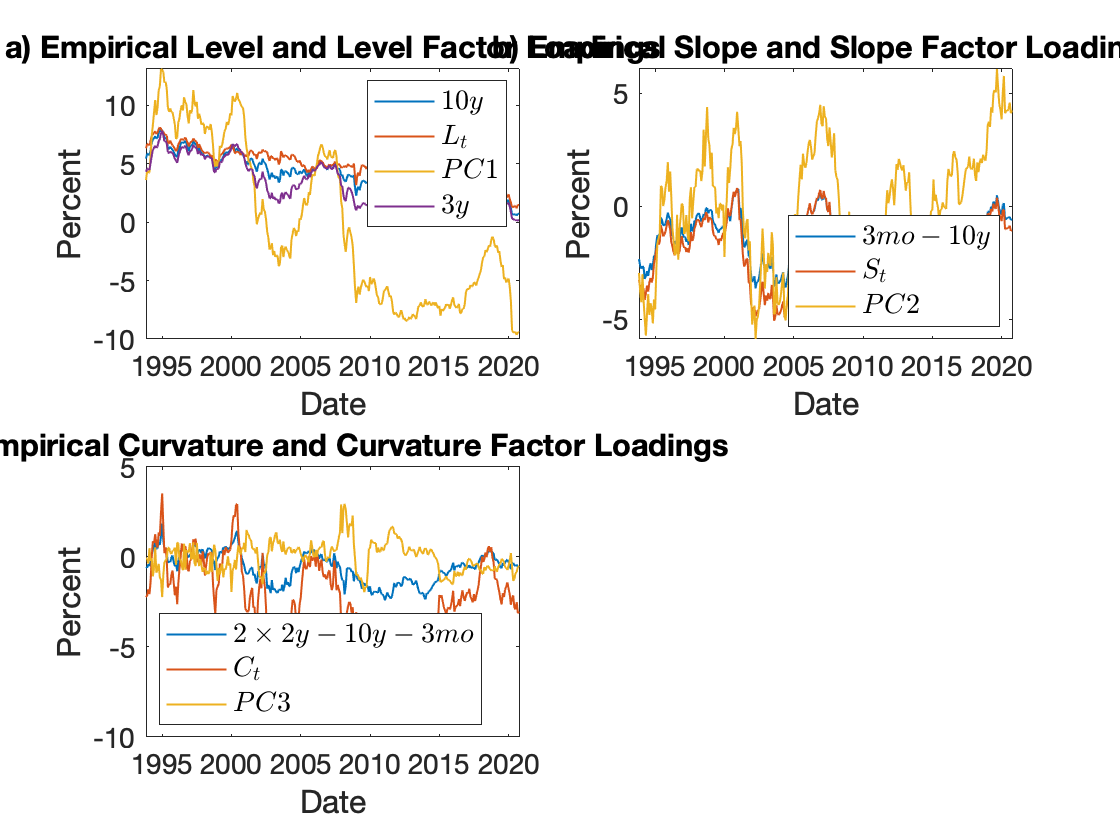

% actual level, slope and curvature from the dataset

% measure of level: L_t
tres_level = tres{:, 'tres10y'};
tres_level1 = tres{:, 'tres3y'};

% measure of slope S_t = yield spread
tres_slope = tres{:, 'tres3mo'} - tres{:, 'tres10y'};

% measure of curvature C_t
tres_curvature = 2*tres{:, 'tres2y'} - tres{:, 'tres10y'} - tres{:, 'tres3mo'};

% stack them together in a matrix for betas
compare_mat = [tres_level tres_slope tres_curvature beta PCs3 tres_level1];


% Convert the matrix into a table with variable names
compare_tab = array2table(compare_mat,...
    'VariableNames',{'level','slope','curvature', 'beta1', 'beta2', 'beta3' ...
    'PC1', 'PC2', 'PC3', '3yr'});

% convert the string of dates into datetime format
dates_dt = array2table(datetime(dates,'InputFormat','yyyy-MM-dd'), ...
    'VariableNames',{'Date'});

% stack the datetime dates with the level, slope and curvature in a table
compare_dt = [dates_dt, compare_tab];

% In each separate graph, plot the level, slope and curvature 
% alsongside its corresponding factor loadings 

figure
subplot(2,2,1)
plot(dates, compare_mat(:,[1,4,7, 10]), 'LineWidth', 1)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',14)
title('a) Empirical Level and Level Factor Loadings','FontSize', 18)
xlabel('Date','FontSize',16)
ylabel('Percent', 'FontSize',16)

legend({'$10y$';'$L_t$'; '$PC 1$'; '$3y$'}, 'FontSize', 14, ...
    'Interpreter', 'latex', 'location','northeast')



subplot(2,2,2)
plot(dates, compare_mat(:,[2,5,8]), 'LineWidth', 1)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',14)
title('b) Empirical Slope and Slope Factor Loadings','FontSize', 18)
xlabel('Date','FontSize', 16)
ylabel('Percent','FontSize', 16)
legend({'$3mo-10y$';'$S_t$'; '$PC 2$'},'FontSize', 14, ...
    'Interpreter', 'latex', 'location','southeast')


subplot(2,2,3)
plot(dates, compare_mat(:,[3,6,9]), 'LineWidth', 1)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',14)
title('c) Empirical Curvature and Curvature Factor Loadings','FontSize', 18)
xlabel('Date','FontSize', 16)
ylabel('Percent','FontSize', 16)
legend({'$2\times2y-10y-3mo$';'$C_t$';'$PC 3$'},'FontSize', 14, ...
    'Interpreter', 'latex','location','southwest')

% Summary stats of the latent variables from the Diebold-Li model (DNS)
beta_pc = [beta PCs3];

tab_beta=table();
tab_beta.Min=min(beta_pc)';
tab_beta.Median=median(beta_pc)';
tab_beta.Mean=mean(beta_pc)'; 
tab_beta.Max=max(beta_pc)';
tab_beta.Std_dev=std(beta_pc)';
tab_beta.Properties.RowNames = {'Level', 'Slope', 'Curvature',...
    'PC 1', 'PC 2', 'PC 3'};

disp_sumstat_beta = {"Summary Statistics of the Latent Variables from  PCA and OLS:";...
    "----------------------------------";...
    tab_beta};
cellfun(@disp,disp_sumstat_beta)

Summary Statistics of the Latent Variables from  PCA and OLS:
----------------------------------
                   Min       Median        Mean          Max      Std_dev
                 _______    ________    ___________    _______    _______

    Level         1.1676      4.8612         4.7201      8.102     1.5496
    Slope        -5.2034     -2.1805        -2.2448    0.80663     1.5414
    Curvature    -7.7157     -2.2111        -2.4515     3.5335     2.3962
    PC 1         -9.6545     -1.8589     1.7215e-15     13.079     6.6352
    PC 2         -5.8663     0.11948     7.9497e-17     6.0712     2.6516
    PC 3         -2.2274    0.011557    -2.0611e-16      2.957    0.84566



The descriptive statistics indicates that PC 1  and PC 3 are the most $\left(\sigma =6\ldotp 6352\right)$ and least volatile $\left(\sigma =0\ldotp 84566\right),$ followed by the level and slope factors, respectively. Evidently, the means of PCs are 0 as they are demeaned values.

The empirical level, slope and curvature factors, alonside their corresponding factor loadings closely follow each other, as also reflected by the high positive correlation with each other :


$$\rho \left(10y\;,\textrm{level}\;\right)=0\ldotp 9607,\;\rho \left(3\textrm{mo}-10y\;,\textrm{slope}\;\right)=0\ldotp 9934,\;\rho \left(2\times 2y-10y,\textrm{curvature}\;\right)=0\ldotp 9769\ldotp \;$$


Likwise, the 10-year yield and yield spread have strong correlations with the first two PCs, respectively, albeit the emprical measure of curvature is negative. 


$$\rho \left(10y\;,\textrm{PC}\;1\;\right)=0\ldotp 9469,\;\rho \left(3\textrm{mo}-10y\;,\textrm{PC}\;2\;\right)=0\ldotp 9034,\;\rho \left(2\times 2y-10y,\textrm{PC}\;3\;\right)=-0\ldotp 4147,\;\rho \left(3y\;,\textrm{PC}\;1\;\right)=0\ldotp 9955\ldotp$$


corr_compare = corrcoef(compare_mat);
rowNames = {'10y','3mo-10y','2*2y-10y-3mo', 'Level', 'Slope', 'Curvature',...
    'PC 1', 'PC 2', 'PC 3', '3y'};
colNames = rowNames;
corr_compare_tab = array2table(corr_compare,'RowNames',rowNames, ...
    'VariableNames',colNames)

corr_compare_tab = 10×10 table
                      10y        3mo-10y     2*2y-10y-3mo      Level        Slope      Curvature       PC 1           PC 2           PC 3          3y    
                    ________    _________    ____________    _________    _________    _________    ___________    ___________    __________    _________

    10y                    1     0.094987       0.56165        0.96073      0.14452     0.59894         0.94698       -0.31644      0.041193      0.94782
    3mo-10y         0.094987            1       0.57853       -0.13561      0.99342      0.5294         0.40572         0.9034     -

Now, through the ACF plots I examined the autocorrelation present in the three latent factors from OLS and three PCs. Both display similar characterstics. $\textrm{PC1}$ and $L_t$ are heavily autocorrelated even after 50 lags, thereby showing high level of persistance. $\textrm{PC2},\textrm{PC3},S_t \;,$ and $C_t$ are relatively less autocorrelated, with the curvature factor showing the least autocorrelation amongst the lags.

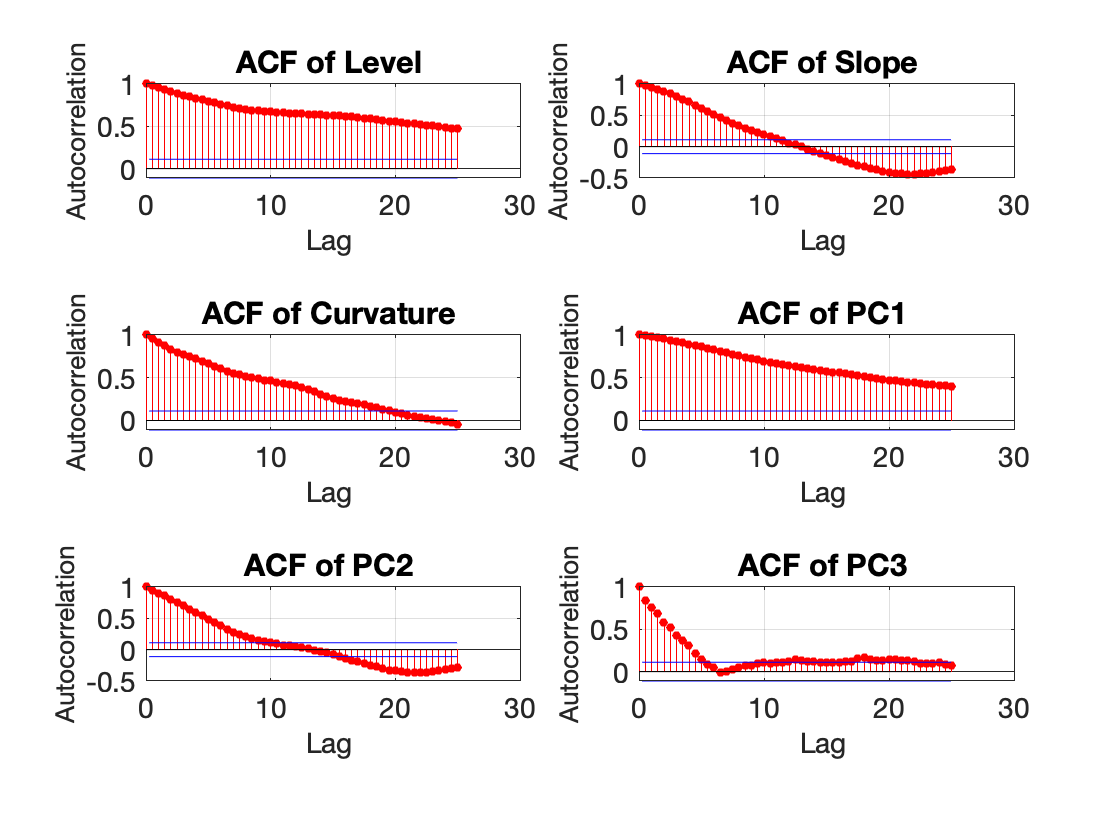


factors = {'Level'; 'Slope'; 'Curvature';'PC1'; 'PC2'; 'PC3'};


figure
hold on
for i=1:size(beta_pc,2)
    subplot(3,2,i)
    autocorr(beta_pc(:,i), 50)
    title(sprintf('ACF of %s ',  factors{i}), 'FontSize', 15);
    a = get(gca,'XTickLabel');
    set(gca,'XTickLabel',a,'fontsize',14)
    
    % label the x-axis and add extra space between two plots
    xlabel("Lag " + newline + "   ", 'FontSize', 14)
    ylabel("Autocorrelation", 'FontSize', 13)
    
  
end
hold off

% ADF test to check for stationarity: STRANGE RESULTS!

% stat_adf = zeros(size(compare_mat,2),3);
% 
% 
% for i = 1: size(compare_mat,2)
%     [h,pValue,stat] = adftest(compare_mat(:,i));
%     stat_adf(i,:) = adftest(compare_mat(:,i));
% end
% 
% 
% ADF_Test = array2table(stat_adf,...
%     'VariableNames',{'Null_rejected','pValue','Test_Statistic'},...
%     'RowNames',{'10y','3mo-10y','2*2y-10y-3mo', 'beta 1', 'beta 2', 'beta 3',...
%     'PC 1', 'PC 2', 'PC 3'})

After fitting the three-dimensional data of factors and obtaining the three PCs, I have fit a first$-$order VAR model  on this estimated time series of factors and PCs separately. 

Whilst conventional procedure of VAR entails no more than six to eight variables in a VAR to conserve degrees of freedom, this information set does not capture the plethora of macroeconomic and financial  time series indicators that central bankers and financial markets use in forecasting macro variables. Since the orthogonal principal components effective summarize the macroeconomic variables, I employed principal components to estimate the yield curve. 

Fitting  VARs on the latent factors (obtained from OLS, and PCA) is the second step of the two-step of the Diebold-Li, and the principal components approach, respectively.  As the  state-space equation works with factors adjusted for mean, I incorporated an additive constant  to the $\textrm{VAR}\left(1\right)$ model. 

% fit a VAR(1) model in the 3D time series of the estimated factors "beta"
% for each of the 324 observations obtained

% "VARmod" stores the estimated parameter values acquired when we fit VAR(1)
% MLE estimates the parameters

VARmod = estimate(varm(3,1), beta);
VARmod_pc = estimate(varm(3,1), PCs3);

% Create a  Bayesian VAR model under conjugate priors
% It specifies the prior distribution of the AR coefficient matrices, model constant vector, 
% and innovations covariance matrix. 
% bayesvarm: displays a summary of the prior distributions 
% numseries = 3; numlags = 1
% BVARmod = estimate(bayesvarm(3,1, 'ModelType','conjugate' ), beta);

% Display summary statistics from the estimation.
varsum = summarize(VARmod);
varsum_pc = summarize(VARmod_pc);

Acoef = VARmod.AR{1};
Acoef_pc = VARmod_pc.AR{1};

% Extract the variance covariance matrix of the innovations of VAR(1)
sigma_eta = VARmod.Covariance;
sigma_eta_pc = VARmod_pc.Covariance;

Then I have forecasted the time series of the latent factors plotted the individual forecasts for 1 year ahead alongside the 95 % forecast intervals. 

mdl =   varm with properties:

     Description: "3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [3×1 vector of NaNs]
              AR: {3×3 matrix of NaNs} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix of NaNs]

Current plot released


Current plot released


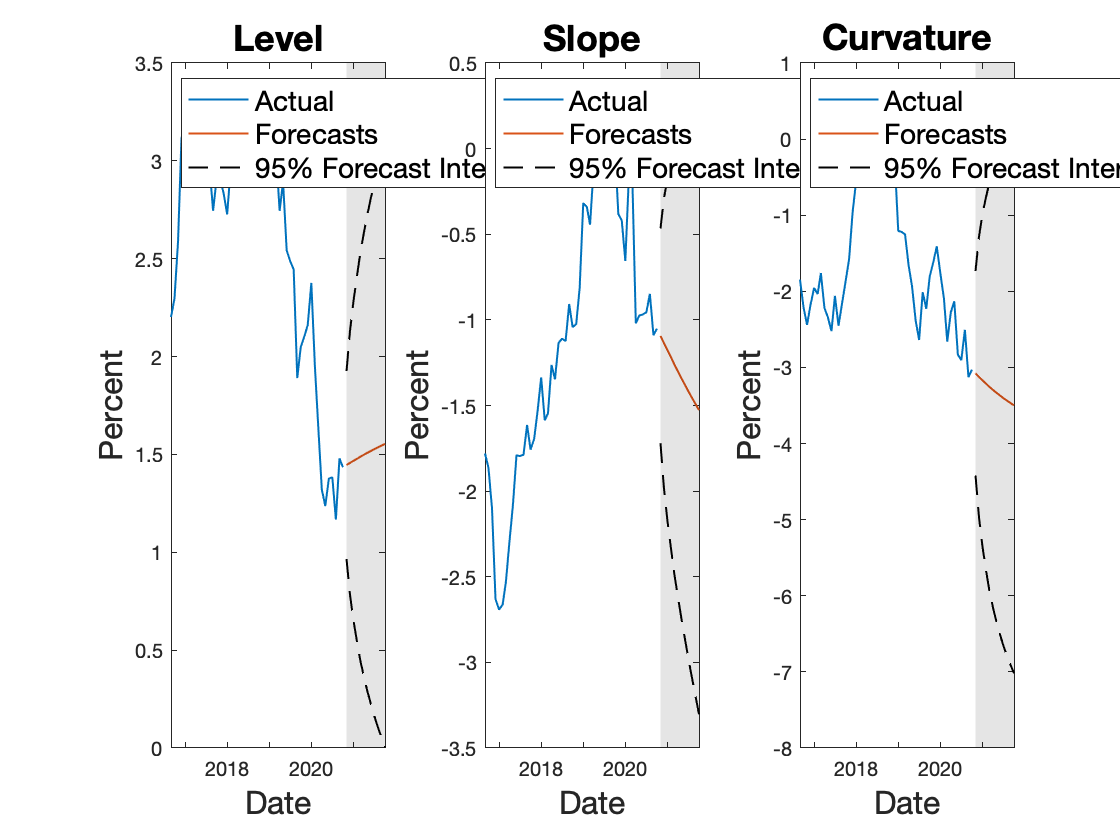

Current plot released


ans =   Line (Actual) with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×50 datetime]
              YData: [1×50 double]
              ZData: [1×0 double]

  Show all properties


% Analyze forecast accuracy using forecast intervals over a one-year horizon
title1 = 'Level';
title2 = 'Slope';
title3 = 'Curvature';

forecast_latent(beta, dates, VARmod, title1, title2, title3)

mdl =   varm with properties:

     Description: "3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [3×1 vector of NaNs]
              AR: {3×3 matrix of NaNs} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix of NaNs]

Current plot released


Current plot released


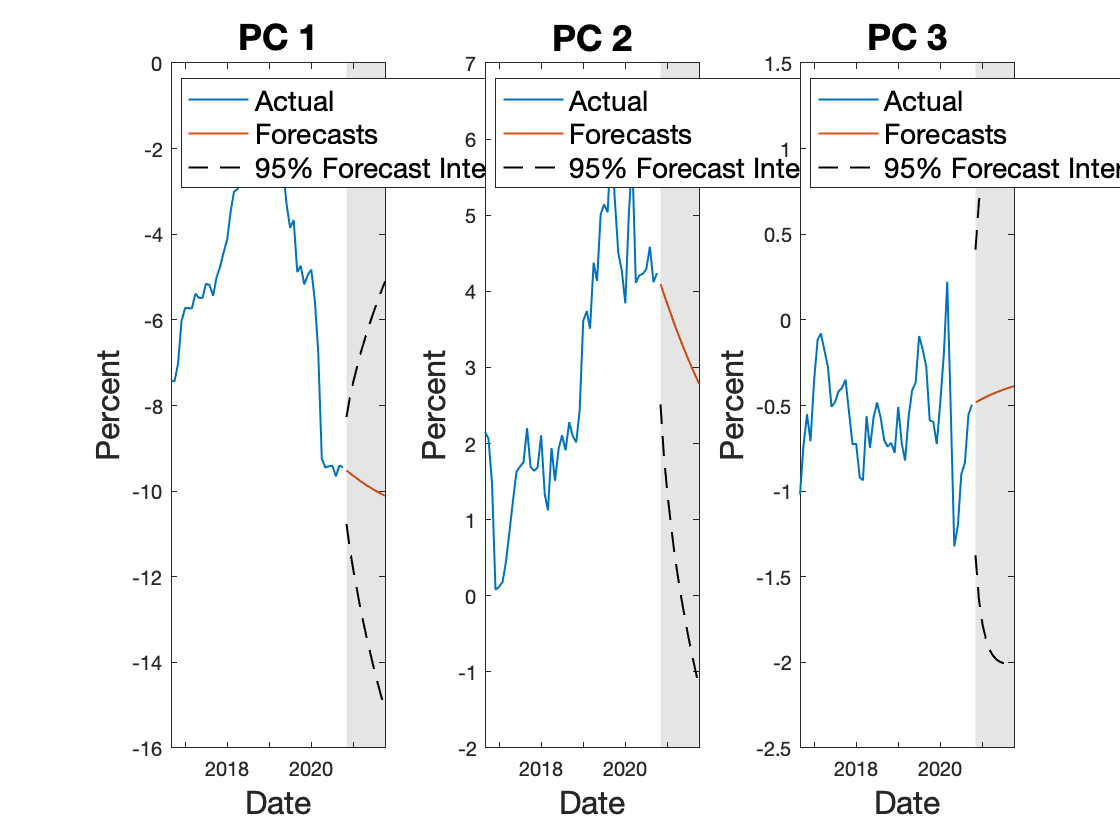

Current plot released


ans =   Line (Actual) with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×50 datetime]
              YData: [1×50 double]
              ZData: [1×0 double]

  Show all properties


title1 = 'PC 1';
title2 = 'PC 2';
title3 = 'PC 3';

forecast_latent(PCs3, dates, VARmod_pc, title1, title2, title3)

## One-Step Kalman Filter  with $\lambda$ as a Random Variable

By specifying a parameter mapping function, I have estimated the Diebold-Li model  implicity. This mapping function maps a parameter vector to SSM model parameters, deflates the observations to account for the means of each factor, and imposes constraints on the covariance matrices. 

% create an SSM model
% pass the parameter mapping function "dns" to the "ssm" function
% the input vector "params" calls the mapping function 
% other input arguments to mapping function: information on yields and time
% to maturity
% link to the mapping function: 
% https://www.mathworks.com/matlabcentral/fileexchange/47479-data_dieboldli-zip

% "ssm" creates a standard, linear, state-space model object with 
% independent Gaussian state disturbances and observation innovations.


model = ssm(@(params)dns(params,yields,ttm));
model_pc = ssm(@(params_pc)dns(params_pc,yields,ttm));

Then, the Kalman filter in the state-space model helps to output maximum likelihood estimates, optimal smoothed and filtered estimates of the latent factors.  However, the Kalman filter can be very sensitive to the initial values of the parameters if we use it to compute the MLE of the SSM model. So, I have initialized the estimation by inputting the results from  the Diebold-Li two-step method to acquire the intial transition matrix.  

Encoded in a column vector are the initial values passed in the SSM `estimate.`While the  matrix $A$ of the SSM model is a $\left(3\times 3\right)$ AR coefficient matrix of the $VAR(1)$ model, it is stacked in a column vector of 9 elements.  Likewise,  the matrix $B$ of the is a $\left(3\times 3\right)$ matrix  such that we can decompose the postive-definite symmetric matrix $\Sigma_\eta$ into a product of two matrices: $B$ and its transpose $:\Sigma_\eta = BB'$. Herein, $B$ is the lower Cholesky factor of $\Sigma_\eta$. To ensure that the off-diagonal elements of the matrix $\Sigma_\eta$ is non-diagonal i.e. the elements are correlated with each other, I have allocated six elements of the lower Cholesky factor $B$ as a column vector of inital parameter values.  Then, I initialized the elements of the initial parameters' vector by taking a square root of the variance of the estimated innovations from the VAR(1) model. Thus, I have assumed diagonality in the covariance matrix $\Sigma_\eta$. As before, I have arranged the initial parameter vector in a manner such that the elements of $B$ along and below the diagonal are stacked as a column vector. 

Just as with matrix $B$, I have constrained the matrix $D$ to be diagonal. This is because the covariance matrix $\Sigma_{\epsilon }$  in the Diebold-Li model is also diagonal, implying that $\Sigma_\epsilon = DD'$. Hence,  the vector of initial parameters is the square root of the diagonal elements of the sample covariance matrix of innovations from $VAR(1).$

Therefore, the elements of the initial parameter vector associated with $D$ are set to the square root of the diagonal elements of the sample covariance matrix of the resid of the $VAR(1)$ model, "one such element for each of the 10 time to maturity of the yields are arranged column-wise.

Unlike other aforementioned matrices in the state-space system, the matrix  $C$ is indirectly estimated. Computed internally by the mapping function, it is a parametarized function of the estimated decay rate parameter $\lambda$. I initialized$\lambda$ to $0\ldotp 0598,$  set the sample average of the three OLS regression coefficients (in the first step) as the vector of initial latent factor parameters. 

In total, the numerical optimization estimates 29 free parameters. These are as as follows:

9  parameters from the$\left(3\times 3\right)$ matrix $A;$ 

3 parameters from the $\left(3\times 1\right)$ vector of means $\mu ;$ 

1 parameter from the measurement matrix $\Lambda ,$ which is the exponential decay rate $\lambda ;$ 

6 parameters from the transition disturbance matrix $\Sigma_{\eta } :$ for each of the three latent factors, I computed the error variance$\;:\sigma_l^2 ,\sigma_s^2 ,\sigma_c^2 \;;$ and three covariance terms $:\sigma_{\textrm{lc}} ,\sigma_{\textrm{ls}} ,\sigma_{\textrm{sc}} \;;$

10 parameters from the measurement disturbance covariance matrix $\Sigma_{\epsilon } :$ for each of the ten yields, I computed the error variances as above. 

% Get the VAR(1) matrix (stored as a cell array)
% A0: 3-by-3 coefficient matrix at lag 1
A0 = VARmod.AR{1}; 

% Columnwise stacking: stacked the above 3-by-3 coefficient matrix into a 
% 9-by-1 column vector
A0 = A0(:);  

% Extract the variance covariance matrix of the innovations of VAR(1)
Sigma_eta = VARmod.Covariance

Sigma_eta =     0.0597   -0.0602    0.0201
   -0.0602    0.1022   -0.0491
    0.0201   -0.0491    0.4681



% B: take the square root of the diagonal elements of Q and other elements
% other elements of Q are 0

B0 = [sqrt(Sigma_eta(1,1)); 0; 0; sqrt(Sigma_eta(2,2)); 0; sqrt(Sigma_eta(3,3))];

% Sigma_eps: 10-by-10 covariance matrix of the residuals from the OLS model
Sigma_eps = cov(resid); 

% diag(Sigma_eps): stores the elements of the main diagonal of the 10-by-10
% matrix D0 as a column vector: 
% it is the square root of the diagonal elements of 
D0 = sqrt(diag(Sigma_eps)); 

% Average of the 3 beta coefficients
mu0 = mean(beta)'

mu0 =     4.7201
   -2.2448
   -2.4515


mu0_pc = mean(PCs3)'

mu0_pc = 	1.0e+-14 *

    0.1722
    0.0079
   -0.0206



% each of the 4 params is a vector, respectively
% param0 stack these 4 vectors into a column vector one below the other
% (vectorize)
% param0: the initial parameter column vector.
% lamda is set to a pre-specified value
% lamda is stored in the last element of param0


param0 = [A0; B0; D0; mu0; lambda0];

After caliberating the initial values, I have established the optimization parameters and estimated the model via the Kalman filter. The Kalman filter outputs the maximum likelihood estimates, optimal filtered and smoothed estimates of the 29 free parameters. As the covariance matrix $\Sigma_\epsilon = DD'$ is diagonal, i.e. the observation innovations are uncorrelated, I have treated the multivariate series as a univariate series. This hastens the estimation's runtime performance, and enhances numerical stability. 

____________________________________________________________
   Diagnostic Information

Number of variables: 29

Functions 
Objective:                            @(c)-fML(c,Mdl,Y,Predictors,unitFlag,sqrtFlag,mexFlag,mexTvFlag,tol,ind,switchTime,precaution)
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)
 

Algorithm selected
   quasi-newton


____________________________________________________________
   End diagnostic information


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0          30         -780.542                      9.52e+04


     1         120         -1515.99    1.05015e-07       4.29e+04  


     2         150         -1673.75              1       1.71e+04  


     3         180         -1708.89              1       6.73e+03  


     4         210         -1756.48              1       6.62e+03  


     5         240         -1873.07              1       1.62e+04  


     6         270         -1964.31              1       1.53e+04  


     7         300         -2023.35              1       9.12e+03  


     8         330         -2043.32              1       3.08e+03  


     9         360         -2046.95              1       1.09e+03  


    10         390         -2048.29              1       1.13e+03  


    11         420         -2051.58              1        2.7e+03  


    12         450         -2058.78              1       4.69e+03  


    13         480         -2073.35              1       6.46e+03  


    14         510         -2089.53              1       5.65e+03  


    15         540          -2097.9              1       2.53e+03  


    16         570         -2104.55              1       1.94e+03  


    17         600         -2105.36              1       1.39e+03  


    18         630         -2107.19              1            674  


    19         660         -2109.18              1       2.63e+03  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
    20         690          -2113.8              1       5.55e+03  


    21         720            -2123              1       8.52e+03  


    22         750         -2137.87              1       8.97e+03  


    23         780         -2149.69              1       5.06e+03  


    24         810         -2152.66              1       2.01e+03  


    25         840          -2153.9              1            921  


    26         870         -2154.62              1       1.35e+03  


    27         900         -2156.78              1       3.29e+03  


    28         930         -2160.61              1       5.15e+03  


    29         960         -2167.79              1       6.62e+03  


    30         990         -2175.24              1       5.81e+03  


    31        1020         -2180.26              1       2.65e+03  


    32        1050         -2182.27              1            984  


    33        1080         -2182.97              1            966  


    34        1110         -2184.14              1       1.56e+03  


    35        1140         -2186.07              1       1.23e+03  


    36        1170         -2190.92              1            764  


    37        1200         -2200.37              1            975  


    38        1230         -2209.37              1       1.25e+03  


    39        1260         -2211.85              1            592  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
    40        1290         -2212.47              1            424  


    41        1320         -2212.87              1            425  


    42        1350         -2213.61              1            596  


    43        1380         -2215.39              1        1.2e+03  


    44        1410         -2219.24              1       1.95e+03  


    45        1440         -2226.13              1       2.42e+03  


    46        1470         -2232.84              1       1.84e+03  


    47        1500         -2235.42              1            901  


    48        1530         -2236.34              1            782  


    49        1560         -2236.94              1            673  


    50        1590         -2237.75              1            854  


    51        1620         -2239.72              1       1.63e+03  


    52        1650         -2243.04              1       2.22e+03  


    53        1680         -2247.86              1        2.2e+03  


    54        1710            -2251              1       1.39e+03  


    55        1740          -2251.4              1            267  


    56        1770         -2251.49              1            278  


    57        1800         -2251.61              1            343  


    58        1830         -2251.98              1            673  


    59        1860         -2252.59              1            913  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
    60        1890         -2253.43              1            868  


    61        1920         -2253.91              1            416  


    62        1950         -2254.03              1            196  


    63        1980         -2254.07              1            188  


    64        2010         -2254.11              1            177  


    65        2040         -2254.25              1            326  


    66        2070         -2254.56              1            510  


    67        2100         -2255.19              1            681  


    68        2130         -2256.09              1            673  


    69        2160         -2256.83              1            396  


    70        2190         -2257.05              1            181  


    71        2220         -2257.09              1            177  


    72        2250         -2257.16              1            171  


    73        2280         -2257.27              1            213  


    74        2310         -2257.41              1            226  


    75        2340         -2257.61              1            217  


    76        2370          -2257.8              1           72.8  


    77        2400         -2257.88              1           80.8  


    78        2430         -2257.93              1            125  


    79        2460         -2257.96              1           69.4  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
    80        2490         -2257.96              1           71.5  


    81        2520         -2257.98              1           74.7  


    82        2550            -2258              1            107  


    83        2580         -2258.07              1            162  


    84        2610         -2258.18              1            202  


    85        2640         -2258.33              1            170  


    86        2670         -2258.41              1             80  


    87        2700         -2258.43              1           84.2  


    88        2730         -2258.44              1           80.1  


    89        2760         -2258.45              1           73.8  


    90        2790         -2258.48              1             66  


    91        2820         -2258.54              1            105  


    92        2850         -2258.68              1            142  


    93        2880         -2258.87              1            142  


    94        2910         -2259.02              1           81.3  


    95        2940         -2259.06              1           49.7  


    96        2970         -2259.07              1           48.3  


    97        3000         -2259.07              1           48.3  


    98        3030         -2259.08              1           48.4  


    99        3060          -2259.1              1           48.5  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   100        3090         -2259.15              1           48.2  


   101        3120         -2259.26              1           52.8  


   102        3150          -2259.5              1           73.8  


   103        3180         -2259.86              1           81.9  


   104        3210         -2260.19              1           95.8  


   105        3240          -2260.3              1           63.3  


   106        3270         -2260.32              1           40.9  


   107        3300         -2260.33              1           42.6  


   108        3330         -2260.33              1           42.5  


   109        3360         -2260.36              1           53.3  


   110        3390         -2260.41              1           70.6  


   111        3420         -2260.53              1           79.7  


   112        3450         -2260.79              1           68.6  


   113        3480         -2261.24              1           75.8  


   114        3510         -2261.65              1           69.4  


   115        3540         -2261.81              1           46.3  


   116        3570         -2261.83              1           48.9  


   117        3600         -2261.84              1             49  


   118        3630         -2261.84              1           48.8  


   119        3660         -2261.86              1           47.8  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   120        3690         -2261.91              1           54.4  


   121        3720            -2262              1           94.1  


   122        3750         -2262.18              1            132  


   123        3780         -2262.37              1           97.7  


   124        3810          -2262.5              1           17.4  


   125        3840         -2262.52              1           32.8  


   126        3870         -2262.52              1           17.4  


   127        3900         -2262.52              1           16.3  


   128        3930         -2262.52              1           16.3  


   129        3960         -2262.52              1           23.6  


   130        3990         -2262.53              1           47.6  


   131        4020         -2262.53              1           84.8  


   132        4050         -2262.55              1            141  


   133        4080         -2262.58              1            214  


   134        4110         -2262.63              1            273  


   135        4140         -2262.71              1            248  


   136        4170         -2262.76              1            124  


   137        4200         -2262.77              1             33  


   138        4230         -2262.77              1           29.6  


   139        4260         -2262.77              1           27.7  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   140        4290         -2262.78              1           46.5  


   141        4320         -2262.79              1           80.9  


   142        4350         -2262.83              1            136  


   143        4380         -2262.91              1            216  


   144        4410          -2263.1              1            314  


   145        4440         -2263.45              1            376  


   146        4470          -2263.8              1            287  


   147        4500         -2263.94              1            105  


   148        4530         -2263.97              1           89.4  


   149        4560         -2263.98              1           88.7  


   150        4590         -2263.99              1           86.9  


   151        4620         -2264.01              1           84.1  


   152        4650         -2264.08              1            115  


   153        4680         -2264.26              1            190  


   154        4710         -2264.66              1            291  


   155        4740          -2265.4              1            376  


   156        4770         -2266.23              1            325  


   157        4800         -2266.63              1            104  


   158        4830         -2266.71              1           40.1  


   159        4860         -2266.72              1           39.6  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   160        4890         -2266.73              1           39.6  


   161        4920         -2266.73              1           39.7  


   162        4950         -2266.74              1           40.2  


   163        4980         -2266.77              1           40.6  


   164        5010         -2266.84              1           54.7  


   165        5040            -2267              1           80.1  


   166        5070         -2267.24              1           88.7  


   167        5100         -2267.43              1           56.2  


   168        5130         -2267.49              1           39.5  


   169        5160          -2267.5              1           37.2  


   170        5190          -2267.5              1           35.9  


   171        5220         -2267.51              1           35.8  


   172        5250         -2267.52              1           35.6  


   173        5280         -2267.56              1           35.1  


   174        5310         -2267.64              1           46.6  


   175        5340         -2267.83              1           71.6  


   176        5370         -2268.14              1           86.2  


   177        5400         -2268.46              1           64.6  


   178        5430         -2268.63              1           40.2  


   179        5460         -2268.66              1           39.1  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   180        5490         -2268.66              1             38  


   181        5520         -2268.66              1           37.3  


   182        5550         -2268.66              1           36.3  


   183        5580         -2268.68              1             35  


   184        5610         -2268.71              1           32.7  


   185        5640         -2268.78              1           54.1  


   186        5670         -2268.93              1           78.7  


   187        5700         -2269.18              1             85  


   188        5730         -2269.41              1           53.7  


   189        5760          -2269.5              1           17.1  


   190        5790         -2269.52              1           13.2  


   191        5820         -2269.52              1           13.8  


   192        5850         -2269.52              1             14  


   193        5880         -2269.52              1           14.4  


   194        5910         -2269.52              1           14.8  


   195        5940         -2269.52              1           15.5  


   196        5970         -2269.53              1           17.6  


   197        6000         -2269.56              1           27.7  


   198        6030          -2269.6              1           36.7  


   199        6060         -2269.67              1           34.4  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   200        6090         -2269.71              1           22.6  


   201        6120         -2269.72              1           21.4  


   202        6150         -2269.72              1             20  


   203        6180         -2269.72              1           19.6  


   204        6210         -2269.73              1           18.7  


   205        6240         -2269.73              1           17.4  


   206        6270         -2269.73              1           14.9  


   207        6300         -2269.74              1           12.2  


   208        6330         -2269.77              1           17.7  


   209        6360         -2269.82              1           20.4  


   210        6390         -2269.86              1           14.4  


   211        6420         -2269.88              1           9.19  


   212        6450         -2269.89              1           9.24  


   213        6480         -2269.89              1           9.22  


   214        6510         -2269.89              1           9.21  


   215        6540         -2269.89              1           9.18  


   216        6570         -2269.89              1           9.11  


   217        6600         -2269.89              1           8.95  


   218        6630         -2269.89              1           8.56  


   219        6660          -2269.9              1           7.65  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   220        6690         -2269.91              1           6.26  


   221        6720         -2269.94              1           7.92  


   222        6750         -2269.96              1           5.98  


   223        6780         -2269.96              1            1.9  


   224        6810         -2269.96              1           1.16  


   225        6840         -2269.96              1           1.19  


   226        6870         -2269.96              1           1.19  


   227        6900         -2269.96              1            1.2  


   228        6930         -2269.96              1            1.2  


   229        6960         -2269.96              1           1.21  


   230        6990         -2269.96              1           1.21  


   231        7020         -2269.96              1           1.45  


   232        7050         -2269.96              1           2.44  


   233        7080         -2269.96              1           3.91  


   234        7110         -2269.96              1            5.3  


   235        7140         -2269.97              1           5.43  


   236        7170         -2269.97              1           3.27  


   237        7200         -2269.97              1           1.13  


   238        7230         -2269.97              1          0.305  


   239        7260         -2269.97              1          0.287  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   240        7290         -2269.97              1          0.286  


   241        7320         -2269.97              1          0.286  


   242        7350         -2269.97              1          0.286  


   243        7380         -2269.97              1          0.285  


   244        7410         -2269.97              1          0.285  


   245        7440         -2269.97              1          0.284  


   246        7470         -2269.97              1          0.382  


   247        7500         -2269.97              1          0.427  


   248        7530         -2269.97              1          0.315  


   249        7560         -2269.97              1          0.286  


   250        7590         -2269.97              1          0.287  


   251        7620         -2269.97              1          0.287  


   252        7650         -2269.97              1          0.287  


   253        7680         -2269.97              1          0.287  


   254        7710         -2269.97              1          0.287  


   255        7740         -2269.97              1          0.286  


   256        7770         -2269.97              1          0.285  


   257        7800         -2269.97              1          0.283  


   258        7830         -2269.97              1           0.28  


   259        7860         -2269.97              1          0.313  


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
   260        7890         -2269.97              1           0.62  


   261        7920         -2269.97              1           1.11  


   262        7950         -2269.97              1           1.88  


   263        7980         -2269.97              1           3.01  


   264        8010         -2269.98              1           4.44  


   265        8040            -2270              1           5.47  


   266        8070         -2270.03              1           4.67  


   267        8100         -2270.04              1           1.65  


   268        8130         -2270.04              1          0.468  


   269        8160         -2270.04              1          0.351  


   270        8190         -2270.04              1         0.0873  


   271        8220         -2270.04              1         0.0358  


   272        8250         -2270.04              1         0.0184  


   273        8280         -2270.04              1         0.0183  


   274        8400         -2270.04        2.43131         0.0184  


   275        8610         -2270.04       0.122663         0.0184  


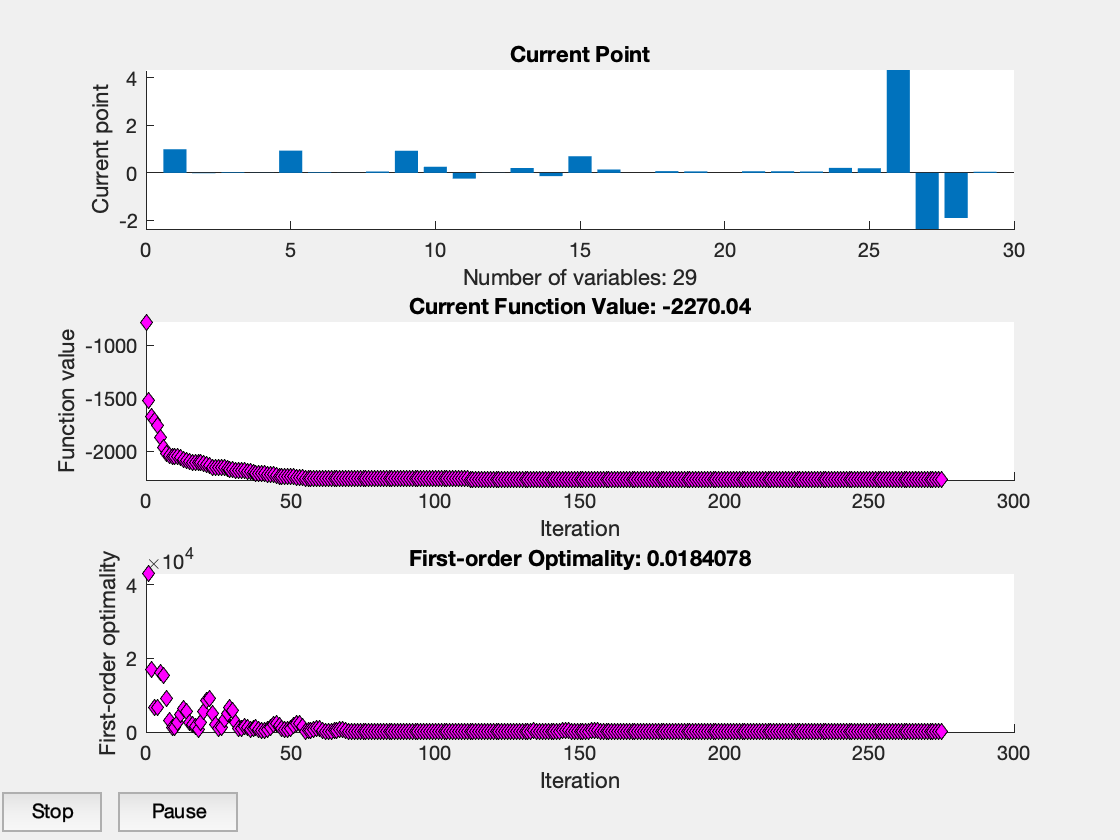


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


Method: Maximum likelihood (fminunc)
Sample size: 324
Logarithmic  likelihood:      2270.04
Akaike   info criterion:     -4482.09
Bayesian info criterion:     -4372.45
       |     Coeff        Std Err      t Stat     Prob  
--------------------------------------------------------
 c(1)  |  0.98905          0.01310    75.48553   0      
 c(2)  | -0.02016          0.01668    -1.20819  0.22698 
 c(3)  |  0.02574          0.04290     0.60002  0.54849 
 c(4)  |  0.00247          0.01572     0.15713  0.87514 
 c(5)  |  0.93380          0.01728    54.04600   0      
 c(6)  |  0.02401          0.03077     0.78015  0.43531 
 c(7)  |  0.00374          0.01042     0.35876  0.71978 
 c(8)  |  0.05828          0.01210     4.81655  0.00000 
 c(9)  |  0.92878          0.02534    36.65435   0      
 c(10) |  0.25785          0.00925    27.86429   0      
 c(11) | -0.24548          0.01664   -14.74959   0      
 c(12) |  0.00350          0.04479     0.07807  0.93777 
 c(13) |  0.20475          0.00640

% create the options for the optimization solver
% MaxFunEvals: maximum number of times the routine evaluates the objective function, 
% each time with the updated parameter estimates.
% fminunc: maximum likelihood 
% maximum number of function evaluations = 30,000
% MaxIter: maximum number of iterations are the iterations of the fminunc function 
% itself. 
% tolerance is a threshold which, if crossed, stops the iterations of a solver.
% TolX: lower bound on the step size
% If the fminunc solver attempts to take a step that is smaller than TolX, 
% the iterations end. 
% TolFun: lower bound on the change in the value of the objective function during 
% a step. 
% PlotFcn: plot various measures of progress during the execution of a solver. 

options = optimoptions('fminunc','MaxFunEvals',30000,'algorithm','quasi-newton', ...
    'TolFun' ,1e-9,'TolX',1e-9,'MaxIter',1100,'Display','off',...
    'PlotFcn',{@optimplotx,@optimplotfval,@optimplotfirstorderopt});

% "estimate" function estimates the SSM model ("model") by the Kalman filter
% SSMmod stores the state-space equation, observation equation, 
% means and the covariance matrix of the initial states
% params: 29-by-1 vector of the updated parameters from SSM
% treat the multivariate series as "univariate": sequential filtering
% estimate the asymptotic covariance by taking the outer product of
% gradients (OPG)

[SSMmod, params] = estimate(model,yields,param0,'Display','full', ...
    'options',options,'Univariate',true);


 % Obtain the estimated lambda or decay rate  
lambda = params(end); 

 % Obtain the estimated factor means
mu = params(end-3:end-1)';  

## Comparing the Estimated Parameters

Below I have contrasted the results yielded from the two-step and SSM methods to analyze the extent of similarities in the results from the aforementioned techniques. Besides, the juxtaposition informs how apt is the use of the two-step approach in establishing the initial parameter values needed to estimate the state-space model. 

First, I have compared the $AR(1)$ coefficient matrix from the VAR model with the state transition matrix $A$ of the SSM model. 

% cellfun: applies the function "disp" to the contents of each cell of cell
% array "display_vars"
% then cellfun concatenates the outputs from "disp" into the output array
% The input argument "disp" is a function handle to a function

disp_ssmA = {"One-Step Kalman Filter: State Transition Matrix (A):";...
    "--------------------------------";...
    SSMmod.A};
cellfun(@disp,disp_ssmA)

One-Step Kalman Filter: State Transition Matrix (A):
--------------------------------
    0.9891    0.0025    0.0037
   -0.0202    0.9338    0.0583
    0.0257    0.0240    0.9288





disp_varA = {"Two-Step Diebold-Li: State Transition Matrix (A) from VAR(1):";...
    "--------------------------------";...
    VARmod.AR{1}}; 
cellfun(@disp,disp_varA)

Two-Step Diebold-Li: State Transition Matrix (A) from VAR(1):
--------------------------------
    0.9961    0.0092   -0.0042
   -0.0272    0.9144    0.0632
    0.0339    0.0252    0.9405





disp_varA_pc = {" Two-Step Principal Components: State Transition Matrix (A) from VAR(1):";...
    "--------------------------------";...
    VARmod_pc.AR{1}}; 
cellfun(@disp,disp_varA_pc)

 Two-Step Principal Components: State Transition Matrix (A) from VAR(1):
--------------------------------
    0.9979   -0.0298   -0.1586
    0.0066    0.9518   -0.2086
    0.0028   -0.0088    0.8426



For comparsion, I have displayed all the coefficients together. The $\left(3\times 3\right)$ matrix A of the latent factors from the Diebold-Li, and PC models, respectively are: 


$$A_1^{2-\textrm{step}} =\left\lbrack \begin{array}{ccc}
0\ldotp 9961 & 0\ldotp 0092 & -0\ldotp 0042\\
-0\ldotp 0272 & 0\ldotp 9144 & 0\ldotp 0632\\
0\ldotp 0339 & 0\ldotp 0252 & 0\ldotp 9405
\end{array}\right\rbrack ,A_1^{2-\textrm{stepPC}} =\left\lbrack \begin{array}{ccc}
0\ldotp 9979 & -0\ldotp 0298 & -0\ldotp 1586\\
0\ldotp 0066 & 0\ldotp 9518 & -0\ldotp 2086\\
0\ldotp 0028 & -0\ldotp 0088 & 0\ldotp 8426
\end{array}\right\rbrack$$


The coefficient matrix A from the one-step Kalman filter approach:


$${{\;A^{1-\textrm{step}} } =\left\lbrack \begin{array}{ccc}
0\ldotp 9890 & 0\ldotp 0025 & 0\ldotp 0037\\
-0\ldotp 0201 & 0\ldotp 9338 & 0\ldotp 0583\\
0\ldotp 0255 & 0\ldotp 0240 & 0\ldotp 9288
\end{array}\right\rbrack \;}$$


Mostly, the results are in agreement. Notably, the large positive diagonal elements of the SSM matrix and the two-step transition matrices $A$ connote high level of persistent dynamics prevalent in each latent factor. Simultaneously, the very low values of othe off-diagonal elements conveys weak covariance between the factors. 

Secondly, I compared the covariance matrix of the innovation $\Sigma_\eta = BB'$ from the state disturbance loading matrix $B$ with the covariance matrix of the innovations from $VAR(1)$ model. The results from both methods are very similar, and the volatility in the state transition shock or the estimated variance (main diagonal elements) of the curvature is the highest, followed by that of slope and curvature, respectively. 

disp_ssmB = {"One-Step: State Error Loading Matrix (B):";...
    "-----------------------------------------";...
    SSMmod.B};
cellfun(@disp,disp_ssmB)

One-Step: State Error Loading Matrix (B):
-----------------------------------------
    0.2578         0         0
   -0.2455    0.2047         0
    0.0035   -0.1399    0.6951



disp_ssmQ = {"One-Step: State Disturbance Covariance Matrix (Sigma_eta = BB''):";...
    "--------------------------------------------------";...
    SSMmod.B * SSMmod.B'};
cellfun(@disp,disp_ssmQ)

One-Step: State Disturbance Covariance Matrix (Sigma_eta = BB''):
--------------------------------------------------
    0.0665   -0.0633    0.0009
   -0.0633    0.1022   -0.0295
    0.0009   -0.0295    0.5028





disp_varQ = {"Two-Step State Diebold-Li: Disturbance Covariance Matrix " + ...
    "(Sigma_eta) from VAR(1):";...
    "-------------------------------------------------";...
    VARmod.Covariance};
cellfun(@disp,disp_varQ)

Two-Step State Diebold-Li: Disturbance Covariance Matrix (Sigma_eta) from VAR(1):
-------------------------------------------------
    0.0597   -0.0602    0.0201
   -0.0602    0.1022   -0.0491
    0.0201   -0.0491    0.4681




disp_varQ_pc = {"Two-Step Principal Components: State Disturbance Covariance Matrix " + ...
    "(Sigma_eta) from VAR(1):";...
    "-------------------------------------------------";...
    VARmod_pc.Covariance};
cellfun(@disp,disp_varQ_pc)

Two-Step Principal Components: State Disturbance Covariance Matrix (Sigma_eta) from VAR(1):
-------------------------------------------------
    0.4036   -0.1993   -0.0164
   -0.1993    0.6533    0.1768
   -0.0164    0.1768    0.2072



The variance-covariance matrix of the innovations of $\textrm{VAR}\left(1\right)$ from the Diebold-Li and PC models, respectively are:


$$\Sigma_{\eta }^{2-\textrm{step}} =\left\lbrack \begin{array}{ccc}
0\ldotp 0597 & -0\ldotp 0602 & 0\ldotp 0201\\
-0\ldotp 0602 & 0\ldotp 1022 & -0\ldotp 0491\\
0\ldotp 0201 & -0\ldotp 0491 & 0\ldotp 4681
\end{array}\right\rbrack ,\Sigma_{\eta }^{2-\textrm{stepPC}} =\left\lbrack \begin{array}{ccc}
0\ldotp 4036 & -0\ldotp 1993 & -0\ldotp 0164\\
-0\ldotp 1993 & 0\ldotp 6533 & 0\ldotp 1768\\
-0\ldotp 0164 & 0\ldotp 1768 & 0\ldotp 2072
\end{array}\right\rbrack$$


The matrix $\Sigma_{\eta }$ from the one-step Kalman filter approach:


$$\Sigma_{\eta }^{1-\textrm{step}} =\left\lbrack \begin{array}{ccc}
0\ldotp 0665 & -0\ldotp 0633 & 0\ldotp 0009\\
-0\ldotp 0633 & 0\ldotp 1022 & -0\ldotp 0295\\
0\ldotp 0009 & -0\ldotp 0295 & 0\ldotp 5028
\end{array}\right\rbrack$$


The lower triangular matrix B from the one-step Kalman filter approach is:


$$Z=\left\lbrack \begin{array}{ccc}
0\ldotp 2578 & 0 & 0\\
-0\ldotp 2455 & 0\ldotp 2047 & 0\\
0\ldotp 0035 & -0\ldotp 1399 & 0\ldotp 6951
\end{array}\right\rbrack$$


Finally, I estimated the means of the level, slope and curvature factors  calculated in the three approaches. The average values are very close to each other in the one-step and two-step Diebold-Li methods, albeit the mean of curvature is slightly smaller in the two-step approach $\left(-2\ldotp 4515\right)$as opposed to that of the one-step method $\left(-1\ldotp 8981\right)\ldotp$ As the PCs are demeaned, the means of first three PCs are close to 0. 

disp_ssm_fmean = {"One-Step Kalman Filter: Factor Means:";...
    "-----------------";...
    mu};
cellfun(@disp,disp_ssm_fmean)

One-Step Kalman Filter: Factor Means:
-----------------
    4.3220   -2.3608   -1.8981




disp_2step_fmean = {"Two-Step Diebold-Li: Factor Means:";...
    "----------------------";...
    mu0'};
cellfun(@disp,disp_2step_fmean)

Two-Step Diebold-Li: Factor Means:
----------------------
    4.7201   -2.2448   -2.4515




disp_2step_fmean_pc = {"Modified Two-Step Diebold-Li: Factor Means:";...
    "----------------------";...
    mu0_pc'};
cellfun(@disp,disp_2step_fmean_pc)

Modified Two-Step Diebold-Li: Factor Means:
----------------------
   1.0e-14 *

    0.1722    0.0079   -0.0206



## Comparing  the Derived Factors

The variables primarily of interest in projecting the ex-ante path of the yield curve are the Diebold-Li model's unobserved factors . While maximum likelihood estimates the unknown parameters,filtering, smoothing and forecasting measure the unobserved states. I have analyzed the states inferred from each approach. The coefficients from the OLS regression in the first step are the latent states (factors). Kalman smoother extracts optimal values of the three factors.The the `smooth` function in the SSM model carries out the Kalman smoothing process wherein the smoothed states for all $t = 1,2,...T$ are:


$$E[x_t|y_T,...,y_1]$$


However, before invoking the `smooth` function, during the estimation, the SSM formulation considers the offset adjustments made to the yields observed. In particular, the parameter mapping function deflates the original yields while estimating. Further, rather than working with the original yields, it works with the offset-adjusted yields $:y'_t = y_t - \Lambda\mu$. The SSM model estimated is oblivious of the adjusted yields as only the mapping function contains the adjustments. Thereby, the other SSM functions such as `smooth`, `filter`, `simulate`, and `forecast `must take into consideration the regression components related to the measurement equation's predictors.  Consequently, I have demeaned the original yields before calling the `smooth` function to ascertain the estimated states. To deflate, I subtracted the intercept corresponding to the estimated offset, $C\mu = \Lambda\mu$, as it counteracts the offset adjustment during the estimation process. Yet, the inferred states are associated with the demeaned, although the actual states (the level, slope, and curvature factors) are variables of interest, rather than their corresponding offset-adjusted values. Therefore, I have readjusted the demeaned states after smoothing by adding the estimated mean, $\mu$, to the factors.

intercept = SSMmod.C * mu';

% demeaned the yields  as the SSM functions such as filter,  smooth, forecast, 
% and simulate, assume that observations are already manually demeaned. 
% offset: Truncate vectors by removing or keeping beginning or ending values

% bsxfun: apply element-wise operation to two arrays with implicit expansion enabled
% subtract the intercept from the yields to get the demeaned yields
dem_yields = bsxfun(@minus,yields,intercept');

% returns smoothed states "dem_states" by performing backward recursion on
% the fully specified state-space model "SSMmod"
% "smooth" applies the standard Kalman filter using "SSMmod" 
% and the responses observed: "dem_yields".
dem_states = smooth(SSMmod,dem_yields); 

% add the estimated means "mu" to the demeaned states (factors)
est_states = bsxfun(@plus,dem_states,mu);

After inferring the states, I have separately plotted the latent factors  derived from the two-step Diebold-Li, modified two-step Diebold-Li and one-step Kalman filter approaches. The plots of the latent factors from all three methods are:

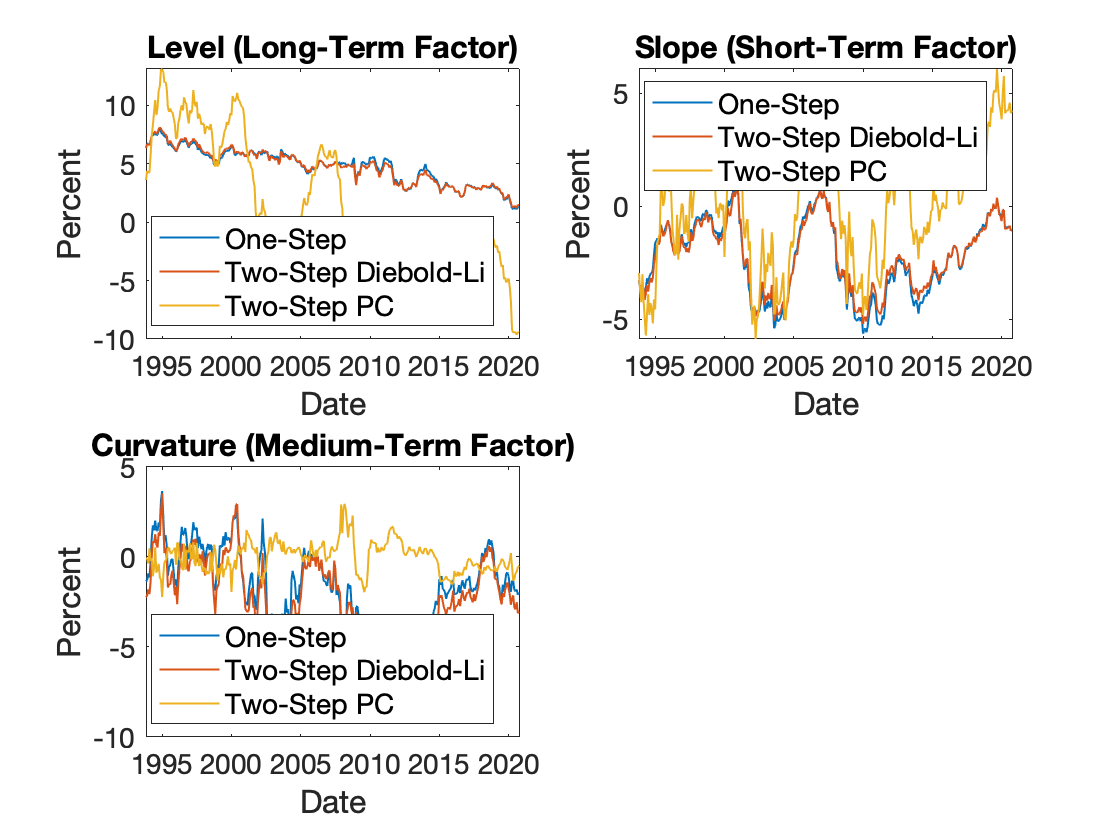

latent = {'Level (Long-Term Factor)', 'Slope (Short-Term Factor)',...
    'Curvature (Medium-Term Factor)'};


for i=1:3
    subplot(2,2,i)
    plot(dates, [est_states(:,i) beta(:,i)  PCs3(:,i)], 'LineWidth', 1)
    a = get(gca,'XTickLabel');
    set(gca,'XTickLabel',a,'fontsize',14)
    title(latent(i), 'FontSize', 18)
    ylabel('Percent', 'FontSize', 16)
    xlabel('Date', 'FontSize', 16)
    legend({'One-Step','Two-Step Diebold-Li', 'Two-Step PC'}, ...
        'location','best', 'FontSize', 14)
  
end

From the separate graphs of all the three factors, the level factor shows considerable persistance as the trajectory indicates a long-term downward trend. Alternatively, the slope and curvature factors are more volatile as they fluctuate from trough to crests, taking in both negative and positive values. Linked with the curvature factor, the estimated decay rate parameter $\lambda$ is $0.0456$. Unlike the constant decay rate applied in the two-step approach where $\lambda$ is  $0.0598,$ the decay rate parameter estimated from the one-step method  is lower. As $\lambda$ from the one-step approach is smaller than the constant $\lambda$, the former (i.e. $\left.\lambda =0\ldotp 0456\right)$ better fits the curve with longer maturities as it slows the rate of decay. 

display_vars = {"One-Step: Rate of Decay (lambda):";...
    "------------------------";...
    lambda};

% apply the function "disp" to each cell of cell array "display_var"
% "disp": displays the value of lamda
cellfun(@disp,display_vars)

One-Step: Rate of Decay (lambda):
------------------------
    0.0456



$\lambda$ determines the time to maturity at which the loading on the curvature is maximized. I have plotted the loading on curvature linked to each value of $\lambda$. Setting $\lambda$ to $0.0598$ maximizes the loading on the curvature at $30$ months. As opposed to the two-step approach, when $\lambda$ is estimated to be $0.0456$ in the one-step approach, the curvature on loading is maximized a decade later in precisely $39\ldotp 5$ months. We can attribute the interpretation of curvature as a medium-term factor to the hump-shape (concave looking) curves as a function of the time to maturity for both values of $\lambda$.  

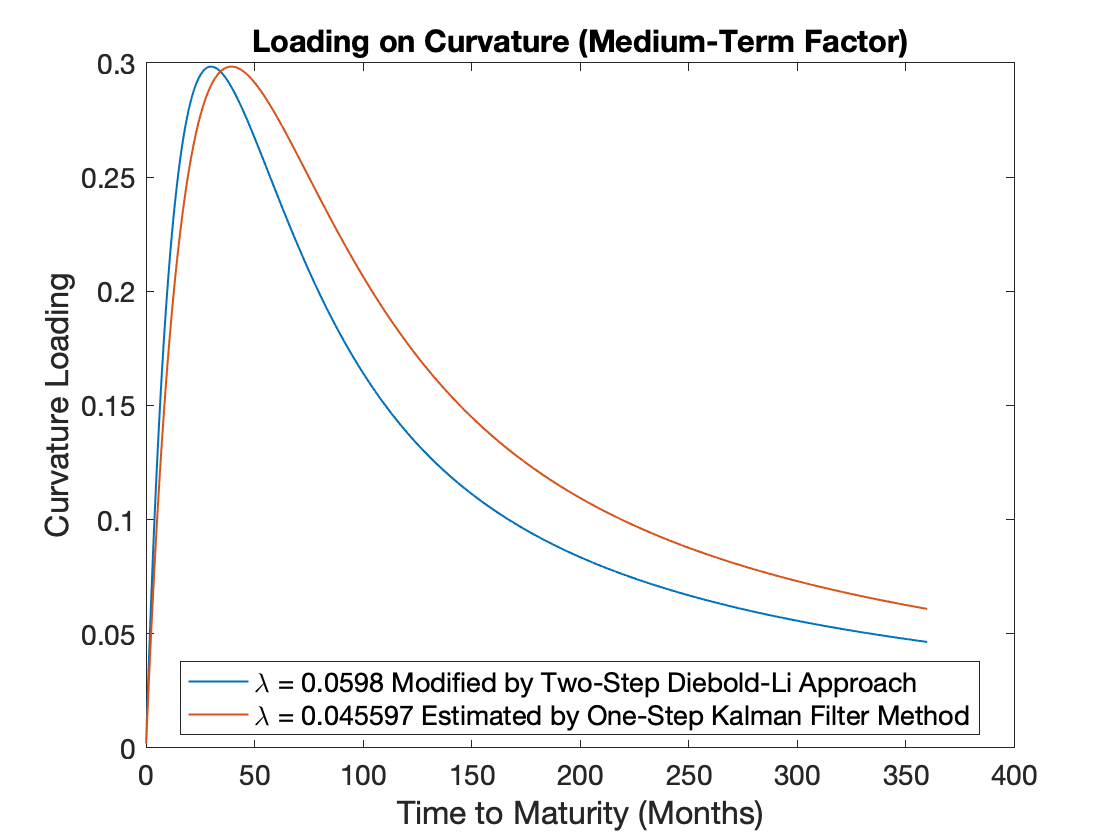

% max(ttm) = 360 and 360*12 = 4320
tau = 0:(1/12):max(ttm);    % time to maturity (months)

% store 3 lambda values from the two-step, one-step, and modified two-step approaches
decay = [lambda0 lambda]; 

% numel(tau): number of elements in "tau" = 4321
% zeros(4321, 3) = 4321-by-3 placeholder matrix of 0s
loading = zeros(numel(tau), 2);

% loadings on the medium-term factor: curvature
for i = 1:numel(tau) % is the same as i = 1: 4321
    loading(i,:) = ((1-exp(-decay*tau(i)))./(decay*tau(i))-exp(-decay*tau(i))); 
end

figure
plot(tau,loading, 'LineWidth',1)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',14)
title('Loading on Curvature (Medium-Term Factor)', 'fontsize',18)
xlabel('Time to Maturity (Months)','fontsize',16)
ylabel('Curvature Loading','fontsize',16)
legend({'\lambda = 0.0598 Modified by Two-Step Diebold-Li Approach ', ...
    ['\lambda = ' num2str(lambda) ' Estimated by One-Step Kalman Filter Method'],}, ...
    'location','best','fontsize',13.5)


xIndex = find(loading == max(loading), 1, 'first');
maxXValue = tau(xIndex);

display_ttm = {"Time to maturity (in months) when lambda = " + ...
    num2str(lambda0) + ...
    " maximizes the loadings on curvature factor:";...
    "------------------------";...
    maxXValue};

% apply the function "disp" to each cell of cell array "display_var"
% "disp": displays the value of lambda
cellfun(@disp,display_ttm)

Time to maturity (in months) when lambda = 0.0598 maximizes the loadings on curvature factor:
------------------------
    30



Albeit differences in the path of the curvature's loading from both the methods, which are prominent after the loadings reach the apex, the factors derived from both methods are reasonably similar. I think I would prefer to use the one-step Kalman filter approach wherein I simultaneously estimated all the parameters. A caveat of the two-step approach is that the second step does not take into account the parameters estimated and the uncertainity associated with extracting signals in the first step.  

Now, I have forecasted the three states 12 months into the future and displayed the forecasts. 

est_states_table = array2table(est_states); 
est_states_date = table2timetable(est_states_table,'RowTimes',dates);

numperiods = 12;
fct_date = dateshift(est_states_date.Time(end),'end','month',1:numperiods);

% dem_fct_states = (12 x 3) matrix of forecasts of the demeaned states 
% XMSE = error variance of the state forecast
[dem_fct_yields, YMSE, dem_fct_states, XMSE] = forecast(SSMmod, 12, dem_yields);
SE = sqrt(XMSE);

% add the estimated means "mu" to the demeaned states (factors)
fct_states = bsxfun(@plus,dem_fct_states,mu);

model = ssm(@(params)dns(params,yields,ttm));
ForecastFI_dem = zeros(numperiods,3,2);
ForecastFI_states = zeros(numperiods,3,2);

% 95 % prediction interval around the demeaned states from Kalman filter
ForecastFI_dem(:,:,1) = dem_fct_states - 1.96*SE;
ForecastFI_dem(:,:,2) = dem_fct_states + 1.96*SE;

FI_states = bsxfun(@plus,ForecastFI_dem,mu);

% Plot the individual forecasts for 1 year ahead alongside the 95 % forecast intervals. 

figure;
subplot(1,3,1);
h1 = plot(est_states_date.Time((end-49):end),est_states((end-49):end,1), ...
    'LineWidth', 1);
hold on;
h2 = plot(fct_date, fct_states(:,1),'LineWidth', 1);
h3 = plot(fct_date,FI_states(:,1,1),'k--','LineWidth', 1);
plot(fct_date,FI_states(:,1,2),'k--','LineWidth', 1);
title('Level','FontSize', 18);
xlabel('Date','FontSize', 16)
ylabel('Percent','FontSize', 16)
h = gca;
fill([fct_date(1) h.XLim([2 2]) fct_date(1)],h.YLim([1 1 2 2]),'k',...
    'FaceAlpha',0.1,'EdgeColor','none');
legend([h1, h2, h3],'Actual','Forecasts','95% Forecast Interval', ...
    'Location','northwest','FontSize', 14)
hold; 

Current plot released





subplot(1,3,2);
h1 = plot(est_states_date.Time((end-49):end),est_states((end-49):end,2), ...
    'LineWidth', 1);
hold on;
h2 = plot(fct_date, fct_states(:,2),'LineWidth', 1);
h3 = plot(fct_date,FI_states(:,2,1),'k--','LineWidth', 1);
plot(fct_date,FI_states(:,2,2),'k--','LineWidth', 1);
title('Slope','FontSize', 18);
xlabel('Date','FontSize', 16)
ylabel('Percent','FontSize', 16)
h = gca;
fill([fct_date(1) h.XLim([2 2]) fct_date(1)],h.YLim([1 1 2 2]),'k',...
    'FaceAlpha',0.1,'EdgeColor','none');
legend([h1, h2, h3],'Actual','Forecasts','95% Forecast Interval', ...
    'Location','northwest','FontSize', 14)
hold; 

Current plot released


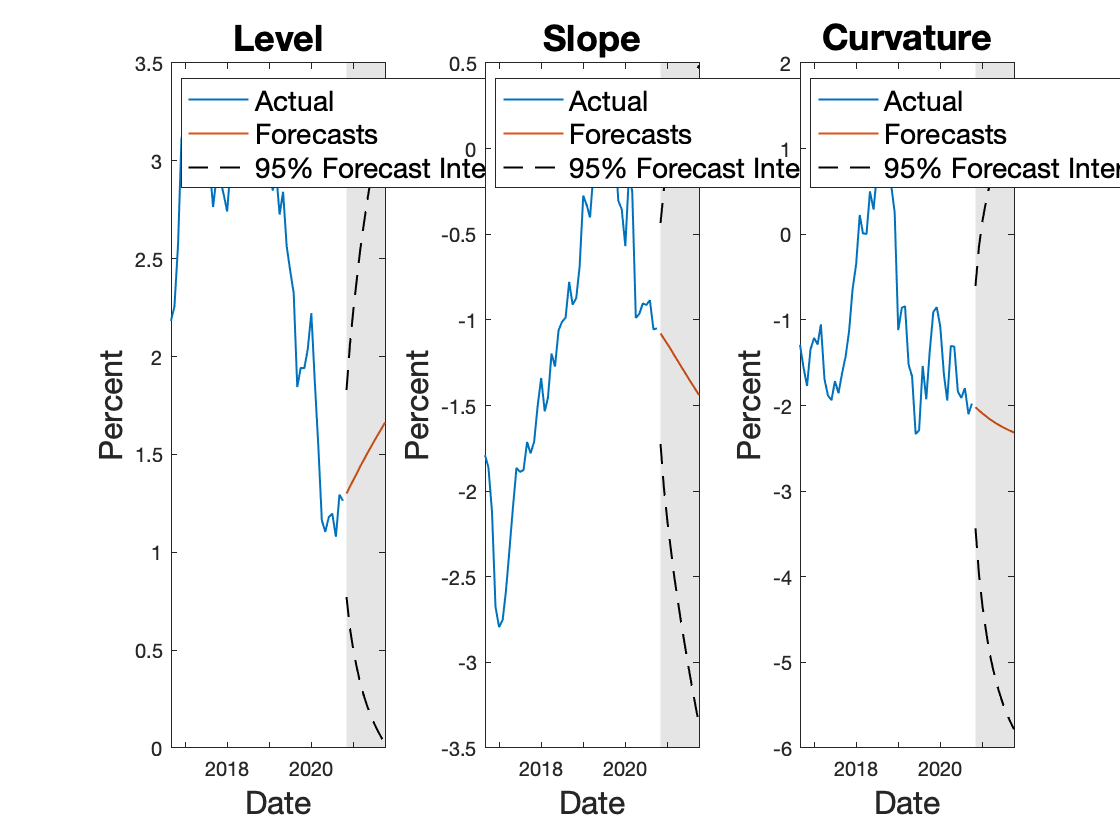

Current plot released





subplot(1,3,3);
h1 = plot(est_states_date.Time((end-49):end),est_states((end-49):end,3), ...
    'LineWidth', 1);
hold on;
h2 = plot(fct_date, fct_states(:,3),'LineWidth', 1);
h3 = plot(fct_date,FI_states(:,3,1),'k--','LineWidth', 1);
plot(fct_date,FI_states(:,3,2),'k--','LineWidth', 1);
title('Curvature','FontSize', 18);
xlabel('Date','FontSize', 16)
ylabel('Percent','FontSize', 16)
h = gca;
fill([fct_date(1) h.XLim([2 2]) fct_date(1)],h.YLim([1 1 2 2]),'k',...
    'FaceAlpha',0.1,'EdgeColor','none');
legend([h1, h2, h3],'Actual','Forecasts','95% Forecast Interval', ...
    'Location','northwest','FontSize', 14)
hold; 

Now, I have contrasted the standard deviations and means of the residuals of the measurement equations from the two methods, and expressed the results in basis points (bps). In the SSM framework, the state measurement sensitivity matrix $C$ is equivalent to the factor loadings matrix  $\Lambda.$ 

% residuals from the one-step Kalman filter approach
resid_SSM = yields - est_states*SSMmod.C';

% residuals from the two-step approach
resid_2step = yields - beta*X';

% residuals from the modified two-step approach
resid_2step_pc = pcares(yields, 3);

% Average and standard deviation of the residuals from the
% One-step Kalman filter approach
resid_avg_ssm = 100*mean(resid_SSM)';
resid_sd_ssm = 100*std(resid_SSM)';

% Average and standard deviation of the residuals from the
% Two-step Diebold-Li approach
resid_avg_2step = 100*mean(resid_2step)';
resid_sd_2step = 100*std(resid_2step)';

% Average and standard deviation of the residuals from the
% Two-step Diebold-Li approach
format shortG
resid_avg_2step_pc = 100*mean(resid_2step_pc)';
resid_sd_2step_pc = 100*std(resid_2step_pc)';

display_vars = {"      ---------------------------------------------------------------------------------";...
    "                         One-Step             Two-Step Diebold-Li    Two-Step PC";...
    "                    -------------------     ------------------      --------------------------";...
    "                               Standard                 Standard                  Standard"  ;...
    "           Maturity    Mean    Deviation      Mean      Deviation       Mean      Deviation"  ;...
    "           (Months)   (bps)      (bps)        (bps)     (bps)           (bps)       (bps)  "  ;...
    "           --------  --------  ---------     -------     ---------     --------    -----------";...
    [ttm resid_avg_ssm resid_sd_ssm resid_avg_2step resid_sd_2step ... 
    resid_avg_2step_pc resid_sd_2step_pc]};

cellfun(@disp,display_vars)

      ---------------------------------------------------------------------------------
                         One-Step             Two-Step Diebold-Li    Two-Step PC
                    -------------------     ------------------      --------------------------
                               Standard                 Standard                  Standard
           Maturity    Mean    Deviation      Mean      Deviation       Mean      Deviation
           (Months)   (bps)      (bps)        (bps)     (bps)           (bps)       (bps)  
           --------  --------  ---------     -------     ---------     --------    -----------
  Columns 1 through 6

            3      -7.9165       11.806      -8.0972       6.9355   4.3432e-14
            6   9.8537e-15   2.6959e-12       2.7708        4.335   2.1117e-14
           12       1.6919       7.2086       7.0419       8.0929  -1.7169e-13
           24       3.2513       5.1181        7.031       5.7206  -1.4323e-14
           36  -4.2469e-13 



%  display_vars = {"  -------------------------------------------------";...
%     "              One-Step             Two-Step";...
%     "            -------------------  ------------------";...
%     "                       Standard            Standard";...
%     "  Maturity    Mean    Deviation    Mean   Deviation";...
%     "  (Months)   (bps)      (bps)     (bps)     (bps)  ";...
%     "  --------  --------  ---------  -------  ---------";...
%     [ttm resid_avg_ssm resid_sd_ssm resid_avg_2step resid_sd_2step]};
% 
% cellfun(@disp,display_vars) 


% Average value of standard deviation from SSM
avg_sd_ssm = mean(resid_sd_ssm);

% Average value of standard deviation from the two-step approach
avg_sd_2step = mean(resid_sd_2step);

% Average value of standard deviation from the modified two-step approach
avg_sd_2step_pc = mean(resid_sd_2step_pc);

disp_avg_ssm = {"Average value of standard deviation from One-Step:";...
    "----------------------------------";...
    avg_sd_ssm};
cellfun(@disp,disp_avg_ssm)

Average value of standard deviation from One-Step:
----------------------------------
       7.2415




disp_avg_2step = {"Average value of standard deviation from Two-Step:";...
    "----------------------------------";...
    avg_sd_2step};
cellfun(@disp,disp_avg_2step)

Average value of standard deviation from Two-Step:
----------------------------------
       6.7754




disp_avg_2step_pc = {"Average value of standard deviation from Two-Step PC:";...
    "----------------------------------";...
    avg_sd_2step_pc};
cellfun(@disp,disp_avg_2step_pc)

Average value of standard deviation from Two-Step PC:
----------------------------------
       5.8435



Though the one-step Kalman filter method fits better for maturities ranging from 6 months to 10 years, the deviation is extrmeley high for the shortest (3 month) and long term maturities (20 and 30 years). These extreme values in standard deviation push the average value of the standard deviation of the residuals from SSM larger $\left(7\ldotp 2415\right),$than that from the two-step approach $\left(6\ldotp 7754\right)\ldotp$ So we can reckon that the the yield curve fitted with the constant $\lambda$ from the  two-step approach generates more accurate, and hence, is preferable to the one-step Kalman filter approach.

## Monte Carlo Simulations and Forecasts

The SSM function enables us to simulate the path of the yield curve by Mone Carlo method and and construct minimum mean square error (MMSE) forecasts. As the Diebold-Li model is founded upon the non-linear combination of the unobserved estimated factors, forecasting the factors is tantamount to forecasting the yield curve. Yet, because I estimated the one-step method  after making the offset adjustment, so the estimates are based on the demeaned yields. Therefore, I have applied the `forecast` function on the demeaned yields to calculate the MMSE foecasts of the demeaned yields 12 months into the future. Then, I added the estimated offset $C\mu$ to the demeaned yields to obtain the  ex-ante foreasts of actual yields and stored it in `forecast_yields.` Since the forecast horizon is set to 12, then for each of the 10 different maturities, `forecast_yields `is a$\;\left(12\times 10\right)$  matrix of forecasts for each time to maturity. 

horizon = 12; % forecast horizon (months)

% call the forecast function on the demeaned yields to compute the MMSE forecasts
[forecast_def_yields,mse] = forecast(SSMmod,horizon,dem_yields);

% add the estimated offset C*mu to the demeaned yields: forecasts of yields
forecast_yields = bsxfun(@plus,forecast_def_yields,intercept');

After enumerating the deterministic MMSE forecasts, I have approximated the same results using Mone Carlo simulation. To ensure that the simulation takes into account the latest information, I initialized covariance matrix and the mean vector of the initial states (factors) from the estimated one-step approach. Thereby, I procured the smoothed states via backward recursion.

% call the smooth function to acquire the smoothed states
% backward recursion  yields the smoothed states
[~,~,results] = smooth(SSMmod,dem_yields);  

% initialize the mean vector at the end of the historical dataset
SSMmod.Mean0 = results(end).SmoothedStates;     
cov0 = results(end).SmoothedStatesCov;

% initialize the covariance matrix 
SSMmod.Cov0 = (cov0 + cov0')/2;                 

Thereafter, I computed the ex-ante yield curve by Monte Carlo simulation $100,000$ times. Each simulation projects the yields of ten different maturities, twelve months into the future, creating a $100,000\times 12\times 10$ dimension of `sim_def_yields. `As before, I have added the factor offsets from the demeaned yields to get the unnormalized yields.  

rng('default') % rng: random number generator

% repeat the simulation 100,000 times
% each path is the ex-ante (simulated) yield curve of the future
nPaths = 100000;
% 100,000 sims of 10 demeaned yields (columns), 12 months in the future (rows)
sim_def_yields = simulate(SSMmod, horizon, nPaths);

% add the estimated offset C*mu to the demeaned yields: forecasts of yields
sim_yields = bsxfun(@plus, sim_def_yields, intercept');

Analogous to the MMSE forecasts and standard errors, I caliberated sample standard deviation and mean of the 100,000 trials. I reordered the matrix of simulated yields to calculate the sample means and standard deviations. The matrix encompasses 100,000 rows, 12 columns, and 10 pages.

% sim_yields: matrix of simulated yields: 100,000 rows, 12 columns and 10 pages
sim_yields = permute(sim_yields,[3 1 2]); % re-order for convenience
forecasts = zeros(horizon,numel(ttm));
std_errors = zeros(horizon,numel(ttm));

for i = 1:numel(ttm)
    forecasts(:,i) = mean(sim_yields(:,:,i));
    std_errors(:,i) = std(sim_yields(:,:,i));
end

Visually comparing the projections and standard errors from MMSE and Monte Carlo methods convey idential paths of the yield curve. 

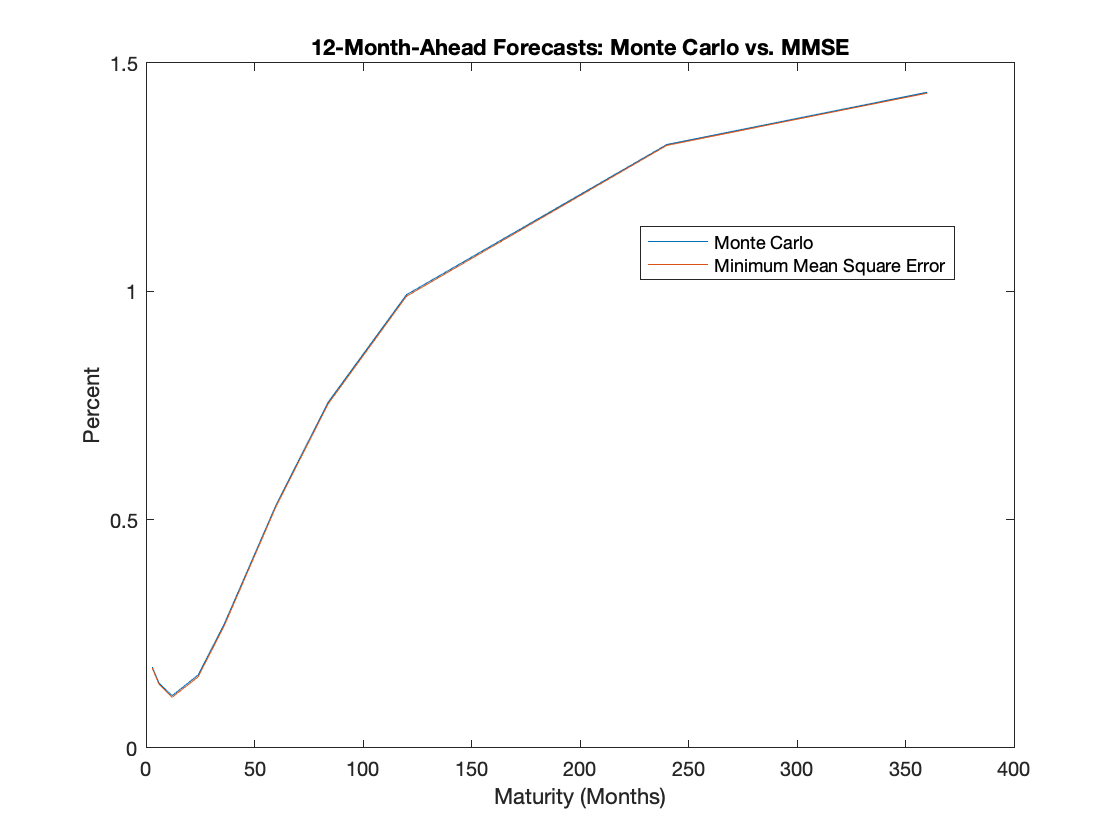

figure
plot(ttm, [forecasts(horizon,:)' forecast_yields(horizon,:)'])
title('12-Month-Ahead Forecasts: Monte Carlo vs. MMSE')
xlabel('Maturity (Months)')
ylabel('Percent')
legend({'Monte Carlo','Minimum Mean Square Error'},'location','best')

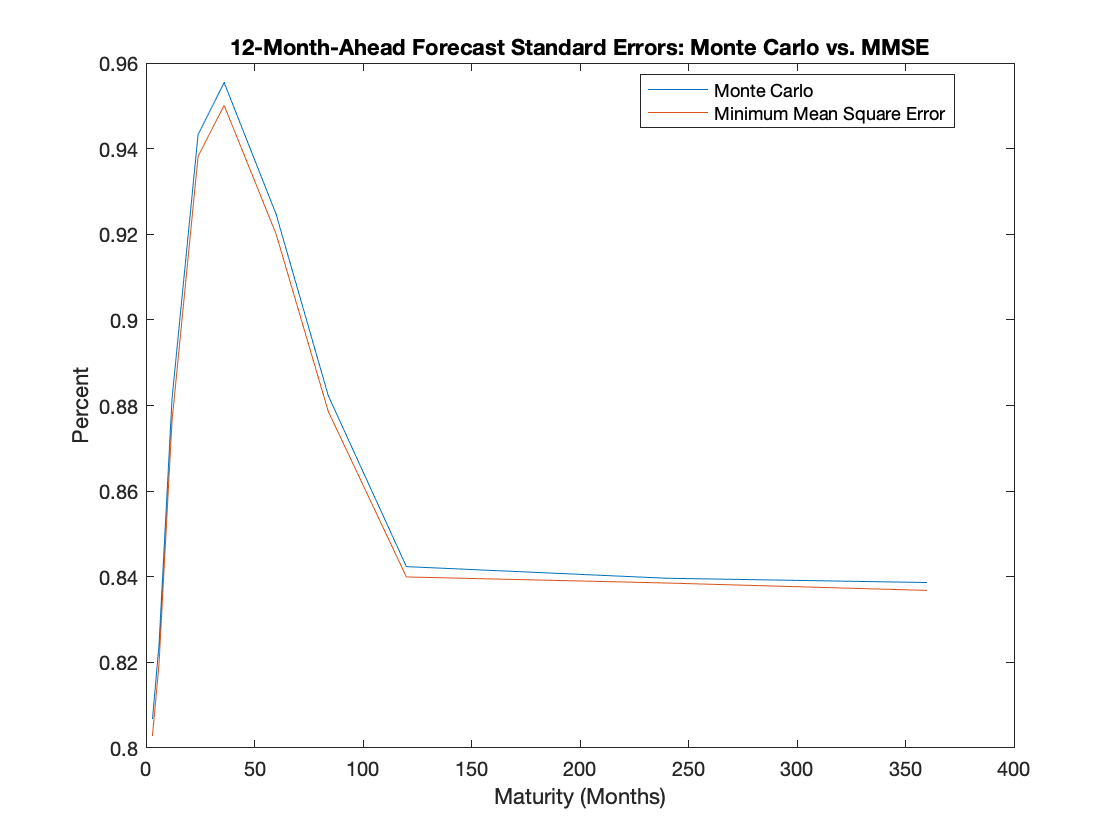


figure
plot(ttm, [std_errors(horizon,:)' sqrt(mse(horizon,:))'])
title('12-Month-Ahead Forecast Standard Errors: Monte Carlo vs. MMSE')
xlabel('Maturity (Months)')
ylabel('Percent')
legend({'Monte Carlo','Minimum Mean Square Error'},'location','best')

Beyond the mean and standard errors, Monte Carlo simulations provide insight into the distribution of yields. As a corollary, we can gauge the distribution of other macroeconomic variables that depend on the yield curve. Next, the plots represent the distibution of the simulated 1 year yield at one, six, and twelve months into the future. 

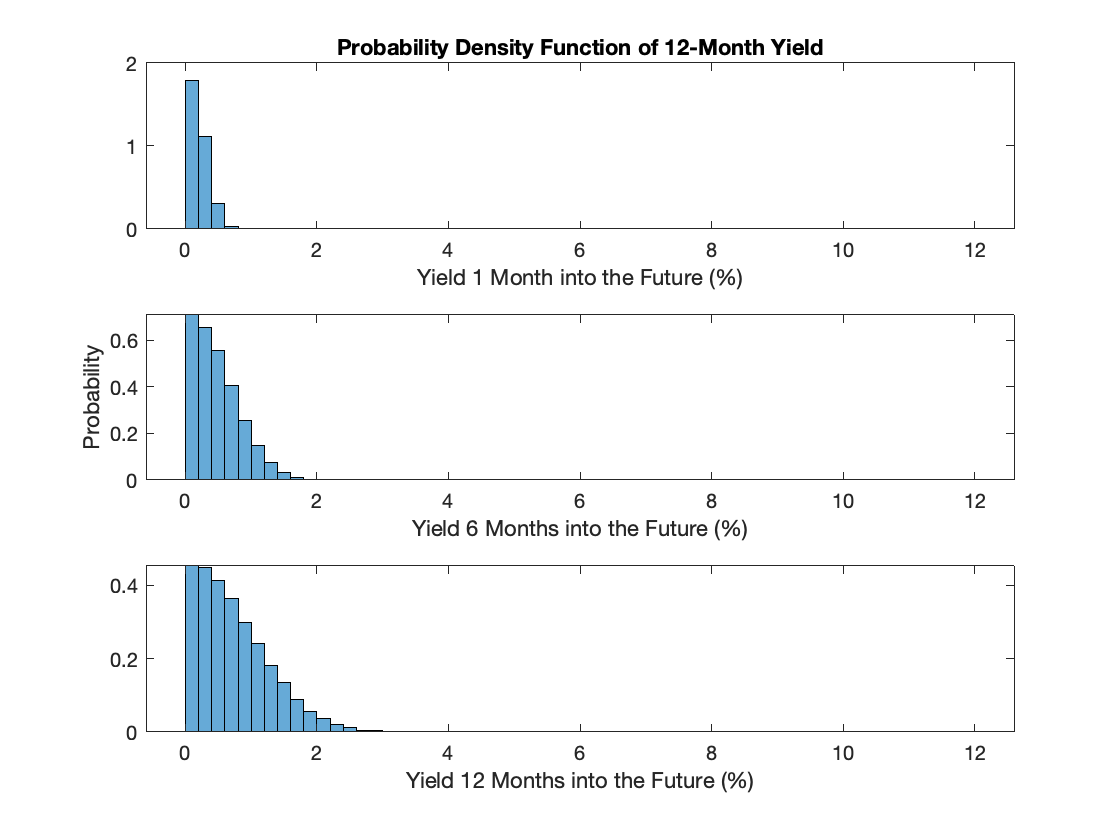

index12 = find(ttm == 12);  % page index of 12-month yield
bins = 0:0.2:12;

% 12-month yield forecasted 1 month into the future
figure
subplot(3,1,1)
histogram(sim_yields(:,1,index12), bins, 'Normalization', 'pdf')
title('Probability Density Function of 12-Month Yield')
xlabel('Yield 1 Month into the Future (%)')

% 12-month yield forecasted 6 months into the future
subplot(3,1,2)
histogram(sim_yields(:,6,index12), bins, 'Normalization', 'pdf')
xlabel('Yield 6 Months into the Future (%)')
ylabel('Probability')

% 12-month yield forecasted 12 months into the future
subplot(3,1,3)
histogram(sim_yields(:,12,index12), bins, 'Normalization', 'pdf')
xlabel('Yield 12 Months into the Future (%)')

## Summary

I have  formulated the Diebold-Li’s two-step approach into a state-space representation by defining the state and measurement equations, and estimated the parameters via the Kalman filter. The one-step Kalman filter  is a stochastic, discrete-time model with two equations: state and measurement equations. The state equation characterizes the transition of the latent (unobserved) states, and the observation equation connects the states to the observed data on yield curve in this analysis. It expresses how we can indirectly caliberate the latent process at each time period. From the time-series of various yield curves, I inferred the three latent states or factors $-$ level, slope, and curvature, that drive the evolution of the term structure of interest rates. Then, applying the functionalities of the one-step , I estimated the parameters using the Kalman filter, smoothed, forecasted and constructed Monte Carlo simulations.

## **References**

Diebold, F. X., & Li, C. (2006). Forecasting the term structure of government bond yields. *Journal of Econometrics,* *130*(2), 337-364. doi:10.1016/j.jeconom.2005.03.005

Diebold, F. X., Rudebusch, G. D., & Aruoba, S. B. (2006). The macroeconomy and the yield curve: A dynamic latent factor approach. *Journal of Econometrics,* *131*(1-2), 309-338. doi:10.1016/j.jeconom.2005.01.011

Diebold, Francis X., and Glenn D. Rudebusch. Yield Curve Modeling and Forecasting: The Dynamic Nelson-Siegel Approach. *Princeton University Press,* 2013. 

Fitting the Diebold Li Model. Retrieved from [https://www.mathworks.com/help/fininst/fitting-the-diebold-li-model_example-ex10300997.html](https://www.mathworks.com/help/fininst/fitting-the-diebold-li-model_example-ex10300997.html) **

Using the Kalman Filter to Estimate and Forecast the Diebold-Li Model. Retrieved from [https://www.mathworks.com/help/econ/using-the-kalman-filter-to-estimate-and-forecast-the-diebold-li-model.html](https://www.mathworks.com/help/econ/using-the-kalman-filter-to-estimate-and-forecast-the-diebold-li-model.html)

**In particular, I acknowledge the signficant help taken from this website, but I have made several additions and modifications. The website served as a useful guide in estimating the state space models for the first time.